# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

You should see output similar to the following:

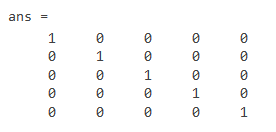

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

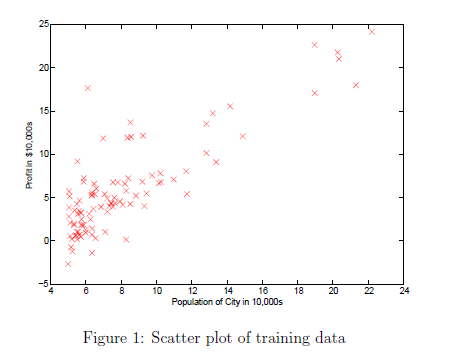

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

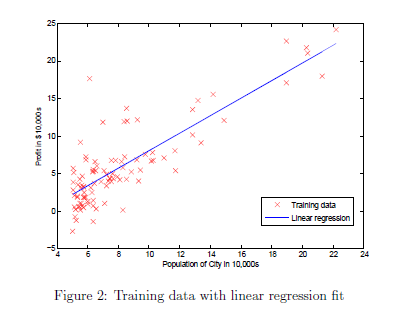    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

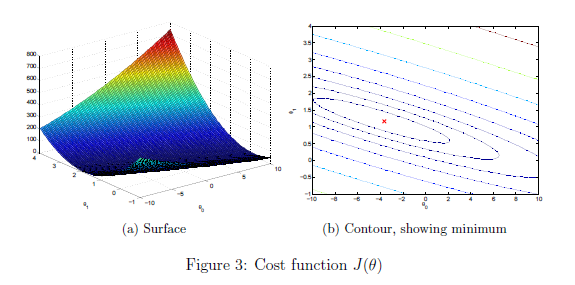

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

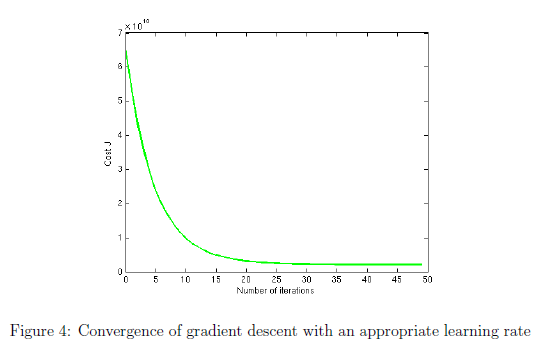

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

delta =      0
     0
     0


delta = 1.0e+05 *

   -3.9990
   -0.5255
    0.9041


delta = 1.0e+05 *

   -7.2980
    1.1558
    1.6500


delta = 1.0e+06 *

   -1.0988
   -0.0718
    0.2484


delta = 1.0e+06 *

   -1.3308
    0.1007
    0.6091


delta = 1.0e+06 *

   -1.8707
   -0.5856
    0.0140


delta = 1.0e+06 *

   -2.1706
   -0.5796
   -0.3166


delta = 1.0e+06 *

   -2.4855
   -0.3927
   -0.2454


delta = 1.0e+06 *

   -2.6845
   -0.2474
   -0.2004


delta = 1.0e+06 *

   -2.8965
   -0.0801
   -0.1525


delta = 1.0e+06 *

   -3.1390
    0.0762
   -0.0976


delta = 1.0e+06 *

   -3.3790
    0.0947
   -0.3622


delta = 1.0e+06 *

   -3.7260
    0.0950
   -0.2837


delta = 1.0e+06 *

   -4.0560
    0.1415
   -0.2091


delta = 1.0e+06 *

   -4.7559
   -2.0639
   -1.9102


delta = 1.0e+06 *

   -5.0158
   -1.8217
   -1.8514


delta = 1.0e+06 *

   -5.4657
   -1.9930
   -2.3473


delta = 1.0e+06 *

   -5.7656
   -1.7333
   -1.8812


delta = 1.0e+06 *

   -5.9655
   -1.5389
   -1.8360


delta = 1.0e+06 *

   -6.4655
   -1.9258
   -2.3871


delta = 1.0e+06 *

   -7.0645
   -2.7108
   -3.0473


delta = 1.0e+06 *

   -7.3174
   -2.6356
   -2.9901


delta = 1.0e+06 *

   -7.5724
   -2.5990
   -2.5937


delta = 1.0e+06 *

   -7.8153
   -2.4765
   -2.5388


delta = 1.0e+06 *

   -8.0752
   -2.4637
   -2.8253


delta = 1.0e+06 *

   -8.6491
   -3.8428
   -2.6955


delta = 1.0e+06 *

   -8.8990
   -3.5565
   -2.6390


delta = 1.0e+06 *

   -9.3635
   -3.2359
   -2.5340


delta = 1.0e+06 *

   -9.8325
   -3.5493
   -2.4280


delta = 1.0e+07 *

   -1.0307
   -0.3670
   -0.2321


delta = 1.0e+07 *

   -1.0607
   -0.3912
   -0.2253


delta = 1.0e+07 *

   -1.0957
   -0.3840
   -0.1709


delta = 1.0e+07 *

   -1.1127
   -0.3624
   -0.1219


delta = 1.0e+07 *

   -1.1442
   -0.3640
   -0.1566


delta = 1.0e+07 *

   -1.2022
   -0.4478
   -0.1435


delta = 1.0e+07 *

   -1.2308
   -0.4409
   -0.1750


delta = 1.0e+07 *

   -1.2558
   -0.4230
   -0.1694


delta = 1.0e+07 *

   -1.2788
   -0.4007
   -0.1642


delta = 1.0e+07 *

   -1.3133
   -0.4065
   -0.2022


delta = 1.0e+07 *

   -1.3682
   -0.5611
   -0.2627


delta = 1.0e+07 *

   -1.3969
   -0.5670
   -0.2943


delta = 1.0e+07 *

   -1.4337
   -0.5512
   -0.2371


delta = 1.0e+07 *

   -1.4667
   -0.5612
   -0.2296


delta = 1.0e+07 *

   -1.4981
   -0.5838
   -0.2642


delta = 1.0e+07 *

   -1.5280
   -0.5533
   -0.2575


delta = 1.0e+07 *

   -1.5460
   -0.5271
   -0.2295


delta = 1.0e+07 *

   -1.5760
   -0.5214
   -0.2625


delta = 1.0e+07 *

   -1.5999
   -0.4971
   -0.2571


delta = 1.0e+05 *

   -3.4041
   -1.0576
   -0.5471


theta = 1.0e+05 *

    3.4041
    1.0576
    0.5471


predictions = 47×1
1.0e+05 *

    3.4194
    2.7414
    3.8176
    1.7672
    5.3515
    3.9860
    2.6526
    2.5087
    2.4455
    2.5988


sqrErrors = 47×1
1.0e+10 *

    0.3359
    0.3109
    0.0163
    0.3056
    0.0023
    0.9742
    0.2464
    0.2690
    0.1059
    0.0302


J = 3.8017e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -5.7958
   -0.7617
    1.3104


delta = 3×1
1.0e+05 *

   -1.1372
    0.2080
    0.2571


delta = 3×1
1.0e+05 *

   -1.0095
    0.2728
    0.2283


delta = 3×1
1.0e+05 *

   -1.5623
    0.6839
    1.0875


delta = 3×1
1.0e+05 *

   -1.6099
    0.6235
    1.0351


delta = 3×1
1.0e+05 *

   -0.6228
    0.6038
    2.1231


delta = 3×1
1.0e+05 *

   -1.1192
    0.8985
    2.2353


delta = 3×1
1.0e+05 *

   -0.6005
    0.5200
    2.1180


delta = 3×1
1.0e+05 *

   -0.2751
    0.2630
    2.0444


delta = 3×1
1.0e+05 *

   -0.1012
    0.1510
    2.0051


delta = 3×1
1.0e+05 *

    1.4243
    0.0333
    3.6865


delta = 3×1
1.0e+05 *

    1.2338
    0.0334
    3.7296


delta = 3×1
1.0e+05 *

    1.0653
    0.0572
    3.7677


delta = 3×1
1.0e+05 *

    2.1328
    3.4207
    6.3621


delta = 3×1
1.0e+05 *

    1.8286
    3.7042
    6.4309


delta = 3×1
1.0e+05 *

    1.7394
    3.6702
    6.3326


delta = 3×1
1.0e+05 *

    0.3784
    4.8485
    8.4480


delta = 3×1
1.0e+05 *

    0.6312
    4.6027
    8.3909


delta = 3×1
1.0e+05 *

    0.4567
    4.4676
    8.1985


delta = 3×1
1.0e+05 *

   -0.1402
    3.6855
    7.5407


delta = 3×1
1.0e+05 *

    0.2969
    3.5556
    7.4419


delta = 3×1
1.0e+05 *

    0.1491
    3.5768
    7.6717


delta = 3×1
1.0e+05 *

    0.4669
    3.4164
    7.5999


delta = 3×1
1.0e+05 *

    1.8229
    3.3497
    9.0946


delta = 3×1
1.0e+05 *

    1.9060
    3.5493
    9.0758


delta = 3×1
1.0e+05 *

    1.4758
    4.0421
    9.1730


delta = 3×1
1.0e+05 *

   -0.6188
    5.4880
    9.6466


delta = 3×1
1.0e+05 *

   -1.3217
    5.0183
    9.8055


delta = 3×1
1.0e+06 *

   -0.2523
    0.4714
    1.0077


delta = 3×1
1.0e+05 *

   -1.3857
    5.6343
    9.8200


delta = 3×1
1.0e+06 *

   -0.2548
    0.5873
    1.1627


delta = 3×1
1.0e+06 *

   -0.3767
    0.7424
    1.5139


delta = 3×1
1.0e+06 *

   -0.2856
    0.7469
    1.6143


delta = 3×1
1.0e+06 *

   -0.3845
    0.6039
    1.6367


delta = 3×1
1.0e+06 *

   -0.2953
    0.5823
    1.7351


delta = 3×1
1.0e+06 *

   -0.2929
    0.5807
    1.7346


delta = 3×1
1.0e+06 *

   -0.2973
    0.5849
    1.7356


delta = 3×1
1.0e+06 *

   -0.2239
    0.5971
    1.8164


delta = 3×1
1.0e+06 *

   -0.0743
    1.0184
    1.9813


delta = 3×1
1.0e+06 *

    0.0611
    1.0462
    2.1306


delta = 3×1
1.0e+06 *

   -0.0973
    1.1141
    2.3768


delta = 3×1
1.0e+06 *

   -0.0672
    1.1231
    2.3700


delta = 3×1
1.0e+06 *

    0.0957
    1.2405
    2.5496


delta = 3×1
1.0e+06 *

    0.0170
    1.3206
    2.5674


delta = 3×1
1.0e+06 *

   -0.0620
    1.4361
    2.6902


delta = 3×1
1.0e+06 *

    0.0188
    1.4208
    2.7793


delta = 3×1
1.0e+06 *

    0.0000
    1.4399
    2.7835


delta = 3×1
1.0e+04 *

    0.0000
    3.0635
    5.9224


theta = 3×1
1.0e+05 *

    3.4041
    0.7513
   -0.0452


predictions = 47×1
1.0e+05 *

    3.5131
    3.0314
    3.7959
    2.9156
    4.3093
    3.3394
    2.9684
    2.8661
    2.8212
    2.9302


sqrErrors = 47×1
1.0e+10 *

    0.2361
    0.0716
    0.0112
    0.3547
    1.1875
    0.1159
    0.0326
    0.7676
    0.4917
    0.2552


J = 2.5947e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.8593
   -0.6386
    1.0987


delta = 3×1
1.0e+04 *

   -7.5348
    0.7250
    1.7036


delta = 3×1
1.0e+04 *

   -6.4756
    1.2630
    1.4641


delta = 3×1
1.0e+04 *

   -0.5196
   -3.1664
   -7.7939


delta = 3×1
1.0e+05 *

   -1.1417
   -1.7017
   -1.9805


delta = 3×1
1.0e+05 *

   -0.8013
   -1.7085
   -1.6053


delta = 3×1
1.0e+05 *

   -0.9819
   -1.6013
   -1.5645


delta = 3×1
1.0e+05 *

   -0.1058
   -2.2406
   -1.7626


delta = 3×1
1.0e+05 *

    0.5954
   -2.7942
   -1.9211


delta = 3×1
1.0e+05 *

    1.1006
   -3.1198
   -2.0353


delta = 3×1
1.0e+05 *

    1.9970
   -3.1889
   -1.0473


delta = 3×1
1.0e+05 *

    1.9407
   -3.1889
   -1.0346


delta = 3×1
1.0e+05 *

    1.9492
   -3.1901
   -1.0365


delta = 3×1
1.0e+05 *

    0.6119
   -7.4040
   -4.2869


delta = 3×1
1.0e+05 *

    0.7271
   -7.5113
   -4.3129


delta = 3×1
1.0e+05 *

   -0.1315
   -7.8382
   -5.2593


delta = 3×1
1.0e+05 *

   -0.3066
   -7.6866
   -4.9871


delta = 3×1
1.0e+05 *

    0.3780
   -8.3525
   -5.1418


delta = 3×1
1.0e+05 *

   -0.6863
   -9.1760
   -6.3149


delta = 3×1
1.0e+06 *

   -0.2337
   -1.1340
   -0.8135


delta = 3×1
1.0e+06 *

   -0.1675
   -1.1536
   -0.8284


delta = 3×1
1.0e+06 *

   -0.0859
   -1.1654
   -0.9554


delta = 3×1
1.0e+06 *

   -0.0252
   -1.1959
   -0.9691


delta = 3×1
1.0e+06 *

    0.0466
   -1.1995
   -0.8899


delta = 3×1
1.0e+06 *

   -0.0053
   -1.3243
   -0.8782


delta = 3×1
1.0e+06 *

    0.0001
   -1.3305
   -0.8794


delta = 3×1
1.0e+06 *

   -0.1748
   -1.2098
   -0.8399


delta = 3×1
1.0e+06 *

   -0.2522
   -1.2615
   -0.8224


delta = 3×1
1.0e+06 *

   -0.3667
   -1.2905
   -0.7965


delta = 3×1
1.0e+06 *

   -0.2643
   -1.2077
   -0.8196


delta = 3×1
1.0e+06 *

   -0.2823
   -1.2040
   -0.7918


delta = 3×1
1.0e+06 *

   -0.1944
   -1.3159
   -1.0452


delta = 3×1
1.0e+06 *

   -0.1701
   -1.3147
   -1.0184


delta = 3×1
1.0e+06 *

   -0.2999
   -1.5024
   -0.9890


delta = 3×1
1.0e+06 *

   -0.2685
   -1.5100
   -0.9544


delta = 3×1
1.0e+06 *

   -0.2309
   -1.5370
   -0.9629


delta = 3×1
1.0e+06 *

   -0.1921
   -1.5745
   -0.9717


delta = 3×1
1.0e+06 *

   -0.1891
   -1.5740
   -0.9684


delta = 3×1
1.0e+06 *

   -0.1911
   -1.5795
   -0.9706


delta = 3×1
1.0e+06 *

   -0.1272
   -1.5664
   -0.9002


delta = 3×1
1.0e+06 *

   -0.1805
   -1.5436
   -0.8174


delta = 3×1
1.0e+06 *

   -0.1463
   -1.5333
   -0.8252


delta = 3×1
1.0e+06 *

   -0.0707
   -1.4789
   -0.7419


delta = 3×1
1.0e+06 *

   -0.1048
   -1.4442
   -0.7342


delta = 3×1
1.0e+06 *

   -0.0470
   -1.5286
   -0.8240


delta = 3×1
1.0e+06 *

   -0.0257
   -1.5326
   -0.8005


delta = 3×1
1.0e+06 *

   -0.0000
   -1.5587
   -0.8063


delta = 3×1
1.0e+04 *

   -0.0000
   -3.3164
   -1.7155


theta = 3×1
1.0e+05 *

    3.4041
    1.0829
    0.1264


predictions = 47×1
1.0e+05 *

    3.5179
    2.8236
    3.9256
    2.4023
    4.9199
    3.5218
    2.7327
    2.5854
    2.5206
    2.6776


sqrErrors = 47×1
1.0e+10 *

    0.2315
    0.2260
    0.0555
    0.0068
    0.2295
    0.2734
    0.1733
    0.3545
    0.1605
    0.0638


J = 2.2162e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.8114
   -0.6323
    1.0878


delta = 3×1
1.0e+04 *

   -9.5649
    1.7903
    2.1626


delta = 3×1
1.0e+04 *

   -7.2091
    2.9868
    1.6299


delta = 3×1
1.0e+04 *

   -6.3859
    2.3747
    0.3504


delta = 3×1
1.0e+05 *

   -1.1177
   -0.3715
   -0.4930


delta = 3×1
1.0e+04 *

   -5.9484
   -3.8192
    0.8326


delta = 3×1
1.0e+05 *

   -1.0111
   -0.1348
    0.1774


delta = 3×1
1.0e+04 *

   -4.1574
   -5.6926
    0.4276


delta = 3×1
1.0e+04 *

   -0.1513
   -8.8553
   -0.4781


delta = 3×1
1.0e+05 *

    0.2375
   -1.0483
   -0.1049


delta = 3×1
1.0e+05 *

    1.2974
   -1.1302
    1.0633


delta = 3×1
1.0e+05 *

    1.2020
   -1.1301
    1.0848


delta = 3×1
1.0e+05 *

    1.1251
   -1.1192
    1.1022


delta = 3×1
1.0e+05 *

    1.2497
   -0.7266
    1.4051


delta = 3×1
1.0e+05 *

    1.0171
   -0.5098
    1.4577


delta = 3×1
1.0e+04 *

    4.7378
   -7.1660
    8.5888


delta = 3×1
1.0e+05 *

   -0.2551
   -0.0855
    1.9919


delta = 3×1
1.0e+05 *

    0.0681
   -0.3999
    1.9188


delta = 3×1
1.0e+05 *

   -0.5505
   -0.8786
    1.2369


delta = 3×1
1.0e+05 *

   -1.5779
   -2.2250
    0.1046


delta = 3×1
1.0e+05 *

   -1.0532
   -2.3809
   -0.0141


delta = 3×1
1.0e+05 *

   -0.5508
   -2.4530
   -0.7951


delta = 3×1
1.0e+05 *

   -0.1506
   -2.6549
   -0.8856


delta = 3×1
1.0e+05 *

    0.7406
   -2.6987
    0.0967


delta = 3×1
1.0e+05 *

    0.9795
   -2.1245
    0.0427


delta = 3×1
1.0e+05 *

    0.6154
   -1.7075
    0.1250


delta = 3×1
1.0e+05 *

   -1.4015
   -0.3153
    0.5810


delta = 3×1
1.0e+05 *

   -1.9924
   -0.7101
    0.7146


delta = 3×1
1.0e+05 *

   -3.0923
   -0.9889
    0.9633


delta = 3×1
1.0e+05 *

   -1.8393
    0.0252
    0.6800


delta = 3×1
1.0e+05 *

   -2.3533
    0.1310
    1.4790


delta = 3×1
1.0e+05 *

   -2.3909
    0.1788
    1.5873


delta = 3×1
1.0e+05 *

   -1.9423
    0.2012
    2.0817


delta = 3×1
1.0e+05 *

   -2.8006
   -1.0393
    2.2758


delta = 3×1
1.0e+05 *

   -2.3774
   -1.1414
    2.7422


delta = 3×1
1.0e+05 *

   -2.2773
   -1.2131
    2.7195


delta = 3×1
1.0e+05 *

   -2.2499
   -1.2397
    2.7133


delta = 3×1
1.0e+05 *

   -1.9755
   -1.1939
    3.0157


delta = 3×1
1.0e+05 *

   -0.8721
    1.9140
    4.2320


delta = 3×1
1.0e+05 *

    0.0236
    2.0978
    5.2191


delta = 3×1
1.0e+05 *

   -0.9175
    2.5008
    6.6819


delta = 3×1
1.0e+05 *

   -0.5141
    2.6226
    6.5907


delta = 3×1
1.0e+05 *

    0.6694
    3.4751
    7.8952


delta = 3×1
1.0e+05 *

   -0.0479
    4.2056
    8.0574


delta = 3×1
1.0e+05 *

   -0.2215
    4.4592
    8.3271


delta = 3×1
1.0e+05 *

    0.1182
    4.3949
    8.7015


delta = 3×1
1.0e+05 *

    0.0000
    4.5148
    8.7282


delta = 3×1
1.0e+04 *

    0.0000
    0.9606
    1.8571


theta = 3×1
1.0e+05 *

    3.4041
    0.9869
   -0.0593


predictions = 47×1
1.0e+05 *

    3.5472
    2.9146
    3.9188
    2.7624
    4.5931
    3.3191
    2.8317
    2.6974
    2.6384
    2.7815


sqrErrors = 47×1
1.0e+10 *

    0.2041
    0.1478
    0.0523
    0.1957
    0.6494
    0.1024
    0.1007
    0.5005
    0.2688
    0.1271


J = 2.0975e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.5177
   -0.5937
    1.0214


delta = 3×1
1.0e+04 *

   -8.3618
    1.3654
    1.8906


delta = 3×1
1.0e+04 *

   -6.0741
    2.5274
    1.3733


delta = 3×1
1.0e+04 *

   -1.6499
   -0.7628
   -5.5036


delta = 3×1
1.0e+05 *

   -0.9709
   -1.1006
   -1.4386


delta = 3×1
1.0e+05 *

   -0.6508
   -1.1070
   -1.0858


delta = 3×1
1.0e+05 *

   -0.9681
   -0.9187
   -1.0141


delta = 3×1
1.0e+05 *

   -0.2606
   -1.4349
   -1.1740


delta = 3×1
1.0e+05 *

    0.2578
   -1.8442
   -1.2913


delta = 3×1
1.0e+05 *

    0.6144
   -2.0739
   -1.3719


delta = 3×1
1.0e+05 *

    1.4770
   -2.1405
   -0.4211


delta = 3×1
1.0e+05 *

    1.4236
   -2.1405
   -0.4091


delta = 3×1
1.0e+05 *

    1.4023
   -2.1375
   -0.4042


delta = 3×1
1.0e+05 *

    0.7728
   -4.1208
   -1.9341


delta = 3×1
1.0e+05 *

    0.6717
   -4.0265
   -1.9112


delta = 3×1
1.0e+05 *

   -0.1129
   -4.3252
   -2.7759


delta = 3×1
1.0e+05 *

   -0.4699
   -4.0161
   -2.2209


delta = 3×1
1.0e+05 *

   -0.0113
   -4.4622
   -2.3246


delta = 3×1
1.0e+05 *

   -0.9089
   -5.1567
   -3.3140


delta = 3×1
1.0e+05 *

   -2.2669
   -6.9363
   -4.8107


delta = 3×1
1.0e+05 *

   -1.6717
   -7.1133
   -4.9453


delta = 3×1
1.0e+05 *

   -0.8668
   -7.2286
   -6.1964


delta = 3×1
1.0e+05 *

   -0.3762
   -7.4762
   -6.3073


delta = 3×1
1.0e+05 *

    0.3150
   -7.5102
   -5.5455


delta = 3×1
1.0e+05 *

    0.3651
   -7.3898
   -5.5568


delta = 3×1
1.0e+05 *

    0.1531
   -7.1469
   -5.5089


delta = 3×1
1.0e+05 *

   -1.7556
   -5.8295
   -5.0773


delta = 3×1
1.0e+05 *

   -2.3686
   -6.2391
   -4.9387


delta = 3×1
1.0e+05 *

   -3.4509
   -6.5135
   -4.6940


delta = 3×1
1.0e+05 *

   -2.2336
   -5.5283
   -4.9692


delta = 3×1
1.0e+05 *

   -2.4393
   -5.4860
   -4.6496


delta = 3×1
1.0e+05 *

   -1.8192
   -6.2752
   -6.4370


delta = 3×1
1.0e+05 *

   -1.5801
   -6.2632
   -6.1734


delta = 3×1
1.0e+05 *

   -2.5353
   -7.6437
   -5.9575


delta = 3×1
1.0e+05 *

   -2.2936
   -7.7020
   -5.6911


delta = 3×1
1.0e+05 *

   -2.0826
   -7.8532
   -5.7388


delta = 3×1
1.0e+05 *

   -1.9202
   -8.0106
   -5.7756


delta = 3×1
1.0e+05 *

   -1.8666
   -8.0017
   -5.7165


delta = 3×1
1.0e+05 *

   -1.2383
   -6.2323
   -5.0241


delta = 3×1
1.0e+05 *

   -0.5671
   -6.0945
   -4.2842


delta = 3×1
1.0e+05 *

   -1.1784
   -5.8328
   -3.3340


delta = 3×1
1.0e+05 *

   -0.7620
   -5.7071
   -3.4282


delta = 3×1
1.0e+05 *

    0.1477
   -5.0519
   -2.4256


delta = 3×1
1.0e+05 *

   -0.4298
   -4.4637
   -2.2950


delta = 3×1
1.0e+05 *

   -0.1744
   -4.8370
   -2.6921


delta = 3×1
1.0e+05 *

   -0.0213
   -4.8659
   -2.5234


delta = 3×1
1.0e+05 *

    0.0000
   -4.8875
   -2.5282


delta = 3×1
1.0e+04 *

    0.0000
   -1.0399
   -0.5379


theta = 3×1
1.0e+05 *

    3.4041
    1.0909
   -0.0055


predictions = 47×1
1.0e+05 *

    3.5487
    2.8494
    3.9594
    2.6015
    4.7846
    3.3763
    2.7579
    2.6094
    2.5442
    2.7024


sqrErrors = 47×1
1.0e+10 *

    0.2027
    0.2021
    0.0726
    0.0792
    0.3775
    0.1423
    0.1530
    0.3837
    0.1799
    0.0769


J = 2.0603e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.5027
   -0.5917
    1.0180


delta = 3×1
1.0e+04 *

   -8.9984
    1.6995
    2.0345


delta = 3×1
1.0e+04 *

   -6.3041
    3.0679
    1.4253


delta = 3×1
1.0e+04 *

   -3.4894
    0.9747
   -2.9498


delta = 3×1
1.0e+04 *

   -9.6334
   -6.8349
   -9.7219


delta = 3×1
1.0e+04 *

   -5.8606
   -6.9101
   -5.5635


delta = 3×1
1.0e+04 *

   -9.7721
   -4.5883
   -4.6791


delta = 3×1
1.0e+04 *

   -3.5781
   -9.1080
   -6.0795


delta = 3×1
1.0e+05 *

    0.0664
   -1.2457
   -0.7039


delta = 3×1
1.0e+05 *

    0.3437
   -1.4244
   -0.7666


delta = 3×1
1.0e+05 *

    1.2576
   -1.4950
    0.2407


delta = 3×1
1.0e+05 *

    1.1920
   -1.4949
    0.2555


delta = 3×1
1.0e+05 *

    1.1438
   -1.4881
    0.2664


delta = 3×1
1.0e+05 *

    0.9728
   -2.0270
   -0.1493


delta = 3×1
1.0e+05 *

    0.7626
   -1.8311
   -0.1017


delta = 3×1
1.0e+05 *

    0.0769
   -2.0921
   -0.8575


delta = 3×1
1.0e+05 *

   -0.4538
   -1.6326
   -0.0325


delta = 3×1
1.0e+05 *

   -0.1084
   -1.9686
   -0.1106


delta = 3×1
1.0e+05 *

   -0.8663
   -2.5550
   -0.9460


delta = 3×1
1.0e+05 *

   -2.0287
   -4.0783
   -2.2272


delta = 3×1
1.0e+05 *

   -1.4766
   -4.2424
   -2.3520


delta = 3×1
1.0e+05 *

   -0.7702
   -4.3437
   -3.4500


delta = 3×1
1.0e+05 *

   -0.3442
   -4.5586
   -3.5463


delta = 3×1
1.0e+05 *

    0.4012
   -4.5953
   -2.7247


delta = 3×1
1.0e+05 *

    0.6890
   -3.9036
   -2.7898


delta = 3×1
1.0e+05 *

    0.3456
   -3.5103
   -2.7122


delta = 3×1
1.0e+05 *

   -1.6470
   -2.1349
   -2.2617


delta = 3×1
1.0e+05 *

   -2.2027
   -2.5063
   -2.1360


delta = 3×1
1.0e+05 *

   -3.2708
   -2.7770
   -1.8945


delta = 3×1
1.0e+05 *

   -1.9815
   -1.7336
   -2.1860


delta = 3×1
1.0e+05 *

   -2.2921
   -1.6697
   -1.7032


delta = 3×1
1.0e+05 *

   -1.9595
   -2.0930
   -2.6620


delta = 3×1
1.0e+05 *

   -1.6559
   -2.0778
   -2.3274


delta = 3×1
1.0e+05 *

   -2.4729
   -3.2586
   -2.1427


delta = 3×1
1.0e+05 *

   -2.1970
   -3.3252
   -1.8386


delta = 3×1
1.0e+05 *

   -2.0728
   -3.4143
   -1.8667


delta = 3×1
1.0e+05 *

   -2.0232
   -3.4623
   -1.8779


delta = 3×1
1.0e+05 *

   -1.8930
   -3.4405
   -1.7344


delta = 3×1
1.0e+04 *

   -9.1258
   -6.7925
   -6.5377


delta = 3×1
1.0e+04 *

   -1.6072
   -5.2498
    1.7495


delta = 3×1
1.0e+05 *

   -0.9001
   -0.2083
    1.3243


delta = 3×1
1.0e+05 *

   -0.4645
   -0.0768
    1.2258


delta = 3×1
1.0e+05 *

    0.5793
    0.6751
    2.3763


delta = 3×1
1.0e+05 *

   -0.1163
    1.3834
    2.5336


delta = 3×1
1.0e+05 *

   -0.0963
    1.3543
    2.5026


delta = 3×1
1.0e+05 *

    0.0964
    1.3179
    2.7150


delta = 3×1
1.0e+05 *

    0.0000
    1.4157
    2.7368


delta = 3×1
1.0e+03 *

    0.0000
    3.0121
    5.8231


theta = 3×1
1.0e+05 *

    3.4041
    1.0607
   -0.0638


predictions = 47×1
1.0e+05 *

    3.5579
    2.8779
    3.9573
    2.7144
    4.6821
    3.3127
    2.7889
    2.6445
    2.5811
    2.7349


sqrErrors = 47×1
1.0e+10 *

    0.1945
    0.1773
    0.0714
    0.1555
    0.5139
    0.0984
    0.1297
    0.4284
    0.2126
    0.0961


J = 2.0486e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.4106
   -0.5796
    0.9972


delta = 3×1
1.0e+04 *

   -8.6211
    1.5662
    1.9492


delta = 3×1
1.0e+04 *

   -5.9482
    2.9239
    1.3448


delta = 3×1
1.0e+04 *

   -2.0043
   -0.0091
   -4.7854


delta = 3×1
1.0e+05 *

   -0.9173
   -0.9121
   -1.2687


delta = 3×1
1.0e+04 *

   -6.0361
   -9.1836
   -9.2293


delta = 3×1
1.0e+04 *

   -9.6371
   -7.0461
   -8.4151


delta = 3×1
1.0e+05 *

   -0.3092
   -1.1822
   -0.9895


delta = 3×1
1.0e+05 *

    0.1520
   -1.5463
   -1.0938


delta = 3×1
1.0e+05 *

    0.4619
   -1.7460
   -1.1638


delta = 3×1
1.0e+05 *

    1.3139
   -1.8118
   -0.2248


delta = 3×1
1.0e+05 *

    1.2615
   -1.8117
   -0.2129


delta = 3×1
1.0e+05 *

    1.2307
   -1.8074
   -0.2060


delta = 3×1
1.0e+05 *

    0.8233
   -3.0913
   -1.1963


delta = 3×1
1.0e+05 *

    0.6543
   -2.9338
   -1.1581


delta = 3×1
1.0e+05 *

   -0.1070
   -3.2237
   -1.9972


delta = 3×1
1.0e+05 *

   -0.5212
   -2.8651
   -1.3535


delta = 3×1
1.0e+05 *

   -0.1333
   -3.2423
   -1.4412


delta = 3×1
1.0e+05 *

   -0.9787
   -3.8965
   -2.3730


delta = 3×1
1.0e+05 *

   -2.2447
   -5.5556
   -3.7684


delta = 3×1
1.0e+05 *

   -1.6705
   -5.7263
   -3.8982


delta = 3×1
1.0e+05 *

   -0.8693
   -5.8411
   -5.1436


delta = 3×1
1.0e+05 *

   -0.4149
   -6.0704
   -5.2463


delta = 3×1
1.0e+05 *

    0.2677
   -6.1040
   -4.4939


delta = 3×1
1.0e+05 *

    0.4963
   -5.5546
   -4.5456


delta = 3×1
1.0e+05 *

    0.2007
   -5.2159
   -4.4787


delta = 3×1
1.0e+05 *

   -1.7580
   -3.8640
   -4.0359


delta = 3×1
1.0e+05 *

   -2.3207
   -4.2400
   -3.9087


delta = 3×1
1.0e+05 *

   -3.3832
   -4.5093
   -3.6684


delta = 3×1
1.0e+05 *

   -2.1052
   -3.4749
   -3.9574


delta = 3×1
1.0e+05 *

   -2.3191
   -3.4309
   -3.6249


delta = 3×1
1.0e+05 *

   -1.7803
   -4.1167
   -5.1781


delta = 3×1
1.0e+05 *

   -1.5424
   -4.1048
   -4.9159


delta = 3×1
1.0e+05 *

   -2.3897
   -5.3295
   -4.7243


delta = 3×1
1.0e+05 *

   -2.1708
   -5.3824
   -4.4830


delta = 3×1
1.0e+05 *

   -2.0117
   -5.4964
   -4.5190


delta = 3×1
1.0e+05 *

   -1.9198
   -5.5854
   -4.5397


delta = 3×1
1.0e+05 *

   -1.8588
   -5.5752
   -4.4725


delta = 3×1
1.0e+05 *

   -1.0274
   -3.2336
   -3.5561


delta = 3×1
1.0e+05 *

   -0.3459
   -3.0938
   -2.8050


delta = 3×1
1.0e+05 *

   -0.9819
   -2.8214
   -1.8163


delta = 3×1
1.0e+05 *

   -0.5422
   -2.6887
   -1.9157


delta = 3×1
1.0e+05 *

    0.4157
   -1.9987
   -0.8599


delta = 3×1
1.0e+05 *

   -0.2360
   -1.3350
   -0.7126


delta = 3×1
1.0e+05 *

   -0.0816
   -1.5606
   -0.9526


delta = 3×1
1.0e+05 *

    0.0527
   -1.5860
   -0.8047


delta = 3×1
1.0e+05 *

    0.0000
   -1.5325
   -0.7927


delta = 3×1
1.0e+03 *

    0.0000
   -3.2607
   -1.6867


theta = 3×1
1.0e+05 *

    3.4041
    1.0933
   -0.0469


predictions = 47×1
1.0e+05 *

    3.5584
    2.8575
    3.9700
    2.6639
    4.7422
    3.3306
    2.7657
    2.6169
    2.5516
    2.7101


sqrErrors = 47×1
1.0e+10 *

    0.1941
    0.1949
    0.0784
    0.1183
    0.4314
    0.1100
    0.1469
    0.3931
    0.1863
    0.0813


J = 2.0450e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.4059
   -0.5790
    0.9961


delta = 3×1
1.0e+04 *

   -8.8207
    1.6710
    1.9943


delta = 3×1
1.0e+04 *

   -6.0203
    3.0934
    1.3611


delta = 3×1
1.0e+04 *

   -2.5811
    0.5357
   -3.9847


delta = 3×1
1.0e+05 *

   -0.9150
   -0.7813
   -1.1224


delta = 3×1
1.0e+04 *

   -5.8331
   -7.8793
   -7.5690


delta = 3×1
1.0e+04 *

   -9.6658
   -5.6043
   -6.7025


delta = 3×1
1.0e+05 *

   -0.3396
   -1.0179
   -0.8120


delta = 3×1
1.0e+05 *

    0.0919
   -1.3586
   -0.9096


delta = 3×1
1.0e+05 *

    0.3770
   -1.5423
   -0.9740


delta = 3×1
1.0e+05 *

    1.2451
   -1.6093
   -0.0172


delta = 3×1
1.0e+05 *

    1.1889
   -1.6093
   -0.0045


delta = 3×1
1.0e+05 *

    1.1497
   -1.6038
    0.0043


delta = 3×1
1.0e+05 *

    0.8860
   -2.4348
   -0.6367


delta = 3×1
1.0e+05 *

    0.6828
   -2.2454
   -0.5907


delta = 3×1
1.0e+05 *

   -0.0475
   -2.5235
   -1.3957


delta = 3×1
1.0e+05 *

   -0.5161
   -2.1178
   -0.6673


delta = 3×1
1.0e+05 *

   -0.1638
   -2.4604
   -0.7469


delta = 3×1
1.0e+05 *

   -0.9653
   -3.0806
   -1.6304


delta = 3×1
1.0e+05 *

   -2.1701
   -4.6594
   -2.9583


delta = 3×1
1.0e+05 *

   -1.6093
   -4.8261
   -3.0851


delta = 3×1
1.0e+05 *

   -0.8390
   -4.9365
   -4.2824


delta = 3×1
1.0e+05 *

   -0.4049
   -5.1555
   -4.3806


delta = 3×1
1.0e+05 *

    0.2947
   -5.1900
   -3.6094


delta = 3×1
1.0e+05 *

    0.5979
   -4.4615
   -3.6780


delta = 3×1
1.0e+05 *

    0.2610
   -4.0756
   -3.6018


delta = 3×1
1.0e+05 *

   -1.7239
   -2.7055
   -3.1530


delta = 3×1
1.0e+05 *

   -2.2686
   -3.0695
   -3.0299


delta = 3×1
1.0e+05 *

   -3.3267
   -3.3377
   -2.7906


delta = 3×1
1.0e+05 *

   -2.0261
   -2.2851
   -3.0847


delta = 3×1
1.0e+05 *

   -2.2729
   -2.2343
   -2.7010


delta = 3×1
1.0e+05 *

   -1.8242
   -2.8054
   -3.9944


delta = 3×1
1.0e+05 *

   -1.5661
   -2.7925
   -3.7099


delta = 3×1
1.0e+05 *

   -2.3702
   -3.9546
   -3.5281


delta = 3×1
1.0e+05 *

   -2.1405
   -4.0100
   -3.2750


delta = 3×1
1.0e+05 *

   -2.0087
   -4.1045
   -3.3048


delta = 3×1
1.0e+05 *

   -1.9522
   -4.1592
   -3.3176


delta = 3×1
1.0e+05 *

   -1.8671
   -4.1450
   -3.2238


delta = 3×1
1.0e+05 *

   -0.9253
   -1.4924
   -2.1857


delta = 3×1
1.0e+05 *

   -0.2185
   -1.3474
   -1.4067


delta = 3×1
1.0e+05 *

   -0.8947
   -1.0578
   -0.3556


delta = 3×1
1.0e+04 *

   -4.4894
   -9.2326
   -4.5643


delta = 3×1
1.0e+04 *

    5.5106
   -2.0293
    6.4578


delta = 3×1
1.0e+04 *

   -1.3769
    4.9850
    8.0150


delta = 3×1
1.0e+04 *

   -0.5710
    3.8076
    6.7625


delta = 3×1
1.0e+04 *

    0.8958
    3.5302
    8.3792


delta = 3×1
1.0e+04 *

    0.0000
    4.4391
    8.5817


delta = 3×1
1.0e+03 *

    0.0000
    0.9445
    1.8259


theta = 3×1
1.0e+05 *

    3.4041
    1.0839
   -0.0651


predictions = 47×1
1.0e+05 *

    3.5613
    2.8665
    3.9694
    2.6993
    4.7100
    3.3107
    2.7755
    2.6280
    2.5632
    2.7203


sqrErrors = 47×1
1.0e+10 *

    0.1916
    0.1871
    0.0781
    0.1439
    0.4747
    0.0972
    0.1395
    0.4070
    0.1964
    0.0872


J = 2.0438e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3770
   -0.5752
    0.9896


delta = 3×1
1.0e+04 *

   -8.7025
    1.6292
    1.9676


delta = 3×1
1.0e+04 *

   -5.9087
    3.0482
    1.3359


delta = 3×1
1.0e+04 *

   -2.1155
    0.2273
   -4.5602


delta = 3×1
1.0e+05 *

   -0.9005
   -0.8530
   -1.2154


delta = 3×1
1.0e+04 *

   -5.8881
   -8.5922
   -8.7185


delta = 3×1
1.0e+04 *

   -9.6235
   -6.3750
   -7.8740


delta = 3×1
1.0e+05 *

   -0.3244
   -1.1030
   -0.9316


delta = 3×1
1.0e+05 *

    0.1188
   -1.4529
   -1.0318


delta = 3×1
1.0e+05 *

    0.4141
   -1.6432
   -1.0986


delta = 3×1
1.0e+05 *

    1.2628
   -1.7087
   -0.1632


delta = 3×1
1.0e+05 *

    1.2107
   -1.7086
   -0.1514


delta = 3×1
1.0e+05 *

    1.1770
   -1.7039
   -0.1438


delta = 3×1
1.0e+05 *

    0.8391
   -2.7685
   -0.9650


delta = 3×1
1.0e+05 *

    0.6488
   -2.5912
   -0.9219


delta = 3×1
1.0e+05 *

   -0.1052
   -2.8783
   -1.7530


delta = 3×1
1.0e+05 *

   -0.5372
   -2.5042
   -1.0815


delta = 3×1
1.0e+05 *

   -0.1716
   -2.8598
   -1.1642


delta = 3×1
1.0e+05 *

   -1.0006
   -3.5013
   -2.0779


delta = 3×1
1.0e+05 *

   -2.2378
   -5.1227
   -3.4416


delta = 3×1
1.0e+05 *

   -1.6701
   -5.2914
   -3.5699


delta = 3×1
1.0e+05 *

   -0.8701
   -5.4061
   -4.8135


delta = 3×1
1.0e+05 *

   -0.4271
   -5.6296
   -4.9137


delta = 3×1
1.0e+05 *

    0.2529
   -5.6630
   -4.1642


delta = 3×1
1.0e+05 *

    0.5375
   -4.9792
   -4.2285


delta = 3×1
1.0e+05 *

    0.2156
   -4.6105
   -4.1557


delta = 3×1
1.0e+05 *

   -1.7587
   -3.2477
   -3.7094


delta = 3×1
1.0e+05 *

   -2.3056
   -3.6131
   -3.5857


delta = 3×1
1.0e+05 *

   -3.3620
   -3.8809
   -3.3469


delta = 3×1
1.0e+05 *

   -2.0649
   -2.8311
   -3.6401


delta = 3×1
1.0e+05 *

   -2.2814
   -2.7866
   -3.3036


delta = 3×1
1.0e+05 *

   -1.7680
   -3.4399
   -4.7834


delta = 3×1
1.0e+05 *

   -1.5305
   -3.4281
   -4.5216


delta = 3×1
1.0e+05 *

   -2.3441
   -4.6039
   -4.3376


delta = 3×1
1.0e+05 *

   -2.1323
   -4.6550
   -4.1042


delta = 3×1
1.0e+05 *

   -1.9895
   -4.7574
   -4.1365


delta = 3×1
1.0e+05 *

   -1.9198
   -4.8250
   -4.1522


delta = 3×1
1.0e+05 *

   -1.8564
   -4.8144
   -4.0824


delta = 3×1
1.0e+05 *

   -0.9613
   -2.2934
   -3.0958


delta = 3×1
1.0e+05 *

   -0.2766
   -2.1529
   -2.3411


delta = 3×1
1.0e+05 *

   -0.9203
   -1.8772
   -1.3404


delta = 3×1
1.0e+05 *

   -0.4733
   -1.7422
   -1.4415


delta = 3×1
1.0e+05 *

    0.4998
   -1.0413
   -0.3690


delta = 3×1
1.0e+04 *

   -1.7524
   -3.5389
   -2.1636


delta = 3×1
1.0e+04 *

   -0.5248
   -5.3325
   -4.0719


delta = 3×1
1.0e+04 *

    0.7587
   -5.5752
   -2.6573


delta = 3×1
1.0e+04 *

    0.0000
   -4.8055
   -2.4857


delta = 3×1
1.0e+03 *

    0.0000
   -1.0224
   -0.5289


theta = 3×1
1.0e+05 *

    3.4041
    1.0941
   -0.0599


predictions = 47×1
1.0e+05 *

    3.5614
    2.8601
    3.9734
    2.6835
    4.7289
    3.3163
    2.7682
    2.6193
    2.5539
    2.7125


sqrErrors = 47×1
1.0e+10 *

    0.1915
    0.1927
    0.0803
    0.1321
    0.4491
    0.1007
    0.1450
    0.3960
    0.1883
    0.0827


J = 2.0434e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3756
   -0.5750
    0.9893


delta = 3×1
1.0e+04 *

   -8.7650
    1.6620
    1.9817


delta = 3×1
1.0e+04 *

   -5.9313
    3.1013
    1.3410


delta = 3×1
1.0e+04 *

   -2.2963
    0.3981
   -4.3091


delta = 3×1
1.0e+05 *

   -0.8998
   -0.8120
   -1.1696


delta = 3×1
1.0e+04 *

   -5.8245
   -8.1832
   -8.1979


delta = 3×1
1.0e+04 *

   -9.6325
   -5.9228
   -7.3369


delta = 3×1
1.0e+05 *

   -0.3339
   -1.0515
   -0.8760


delta = 3×1
1.0e+05 *

    0.0999
   -1.3940
   -0.9741


delta = 3×1
1.0e+05 *

    0.3875
   -1.5793
   -1.0391


delta = 3×1
1.0e+05 *

    1.2412
   -1.6452
   -0.0981


delta = 3×1
1.0e+05 *

    1.1879
   -1.6452
   -0.0861


delta = 3×1
1.0e+05 *

    1.1515
   -1.6401
   -0.0778


delta = 3×1
1.0e+05 *

    0.8588
   -2.5626
   -0.7895


delta = 3×1
1.0e+05 *

    0.6578
   -2.3753
   -0.7440


delta = 3×1
1.0e+05 *

   -0.0865
   -2.6587
   -1.5644


delta = 3×1
1.0e+05 *

   -0.5356
   -2.2699
   -0.8663


delta = 3×1
1.0e+05 *

   -0.1811
   -2.6147
   -0.9465


delta = 3×1
1.0e+05 *

   -0.9964
   -3.2455
   -1.8451


delta = 3×1
1.0e+05 *

   -2.2144
   -4.8417
   -3.1876


delta = 3×1
1.0e+05 *

   -1.6509
   -5.0091
   -3.3149


delta = 3×1
1.0e+05 *

   -0.8606
   -5.1224
   -4.5435


delta = 3×1
1.0e+05 *

   -0.4240
   -5.3427
   -4.6422


delta = 3×1
1.0e+05 *

    0.2614
   -5.3764
   -3.8868


delta = 3×1
1.0e+05 *

    0.5693
   -4.6364
   -3.9564


delta = 3×1
1.0e+05 *

    0.2345
   -4.2529
   -3.8808


delta = 3×1
1.0e+05 *

   -1.7480
   -2.8844
   -3.4325


delta = 3×1
1.0e+05 *

   -2.2893
   -3.2461
   -3.3101


delta = 3×1
1.0e+05 *

   -3.3443
   -3.5135
   -3.0716


delta = 3×1
1.0e+05 *

   -2.0401
   -2.4580
   -3.3665


delta = 3×1
1.0e+05 *

   -2.2669
   -2.4113
   -3.0139


delta = 3×1
1.0e+05 *

   -1.7818
   -3.0287
   -4.4122


delta = 3×1
1.0e+05 *

   -1.5380
   -3.0165
   -4.1434


delta = 3×1
1.0e+05 *

   -2.3379
   -4.1728
   -3.9626


delta = 3×1
1.0e+05 *

   -2.1228
   -4.2247
   -3.7254


delta = 3×1
1.0e+05 *

   -1.9886
   -4.3209
   -3.7557


delta = 3×1
1.0e+05 *

   -1.9299
   -4.3777
   -3.7690


delta = 3×1
1.0e+05 *

   -1.8590
   -4.3659
   -3.6909


delta = 3×1
1.0e+05 *

   -0.9293
   -1.7474
   -2.6661


delta = 3×1
1.0e+05 *

   -0.2366
   -1.6053
   -1.9027


delta = 3×1
1.0e+05 *

   -0.8930
   -1.3242
   -0.8824


delta = 3×1
1.0e+05 *

   -0.4441
   -1.1887
   -0.9839


delta = 3×1
1.0e+04 *

    5.4220
   -4.7824
    1.0316


delta = 3×1
1.0e+04 *

   -1.4441
    2.2102
    2.5839


delta = 3×1
1.0e+04 *

   -0.4480
    0.7549
    1.0357


delta = 3×1
1.0e+04 *

    0.8744
    0.5048
    2.4932


delta = 3×1
1.0e+04 *

    0.0000
    1.3919
    2.6909


delta = 3×1
    0.0000
  296.1561
  572.5346


theta = 3×1
1.0e+05 *

    3.4041
    1.0912
   -0.0656


predictions = 47×1
1.0e+05 *

    3.5624
    2.8629
    3.9732
    2.6946
    4.7188
    3.3101
    2.7713
    2.6228
    2.5575
    2.7157


sqrErrors = 47×1
1.0e+10 *

    0.1907
    0.1902
    0.0802
    0.1403
    0.4627
    0.0968
    0.1427
    0.4004
    0.1914
    0.0845


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3665
   -0.5738
    0.9872


delta = 3×1
1.0e+04 *

   -8.7279
    1.6489
    1.9733


delta = 3×1
1.0e+04 *

   -5.8963
    3.0872
    1.3331


delta = 3×1
1.0e+04 *

   -2.1503
    0.3014
   -4.4896


delta = 3×1
1.0e+05 *

   -0.8952
   -0.8345
   -1.1987


delta = 3×1
1.0e+04 *

   -5.8417
   -8.4067
   -8.5583


delta = 3×1
1.0e+04 *

   -9.6192
   -6.1645
   -7.7043


delta = 3×1
1.0e+05 *

   -0.3292
   -1.0782
   -0.9135


delta = 3×1
1.0e+05 *

    0.1084
   -1.4236
   -1.0124


delta = 3×1
1.0e+05 *

    0.3991
   -1.6109
   -1.0781


delta = 3×1
1.0e+05 *

    1.2467
   -1.6764
   -0.1439


delta = 3×1
1.0e+05 *

    1.1947
   -1.6763
   -0.1321


delta = 3×1
1.0e+05 *

    1.1601
   -1.6714
   -0.1243


delta = 3×1
1.0e+05 *

    0.8441
   -2.6673
   -0.8924


delta = 3×1
1.0e+05 *

    0.6471
   -2.4838
   -0.8479


delta = 3×1
1.0e+05 *

   -0.1046
   -2.7700
   -1.6765


delta = 3×1
1.0e+05 *

   -0.5422
   -2.3911
   -0.9962


delta = 3×1
1.0e+05 *

   -0.1836
   -2.7399
   -1.0773


delta = 3×1
1.0e+05 *

   -1.0074
   -3.3774
   -1.9854


delta = 3×1
1.0e+05 *

   -2.2356
   -4.9869
   -3.3391


delta = 3×1
1.0e+05 *

   -1.6700
   -5.1550
   -3.4670


delta = 3×1
1.0e+05 *

   -0.8703
   -5.2696
   -4.7100


delta = 3×1
1.0e+05 *

   -0.4309
   -5.4913
   -4.8093


delta = 3×1
1.0e+05 *

    0.2482
   -5.5248
   -4.0608


delta = 3×1
1.0e+05 *

    0.5504
   -4.7987
   -4.1291


delta = 3×1
1.0e+05 *

    0.2203
   -4.4206
   -4.0544


delta = 3×1
1.0e+05 *

   -1.7590
   -3.0544
   -3.6070


delta = 3×1
1.0e+05 *

   -2.3009
   -3.4165
   -3.4844


delta = 3×1
1.0e+05 *

   -3.3553
   -3.6839
   -3.2460


delta = 3×1
1.0e+05 *

   -2.0522
   -2.6292
   -3.5406


delta = 3×1
1.0e+05 *

   -2.2696
   -2.5845
   -3.2028


delta = 3×1
1.0e+05 *

   -1.7642
   -3.2277
   -4.6596


delta = 3×1
1.0e+05 *

   -1.5268
   -3.2158
   -4.3979


delta = 3×1
1.0e+05 *

   -2.3298
   -4.3764
   -4.2164


delta = 3×1
1.0e+05 *

   -2.1202
   -4.4270
   -3.9854


delta = 3×1
1.0e+05 *

   -1.9826
   -4.5256
   -4.0165


delta = 3×1
1.0e+05 *

   -1.9197
   -4.5865
   -4.0307


delta = 3×1
1.0e+05 *

   -1.8556
   -4.5758
   -3.9601


delta = 3×1
1.0e+05 *

   -0.9406
   -1.9985
   -2.9515


delta = 3×1
1.0e+05 *

   -0.2548
   -1.8578
   -2.1957


delta = 3×1
1.0e+05 *

   -0.9010
   -1.5811
   -1.1912


delta = 3×1
1.0e+05 *

   -0.4517
   -1.4455
   -1.2928


delta = 3×1
1.0e+04 *

    5.2612
   -7.4112
   -2.1503


delta = 3×1
1.0e+04 *

   -1.5618
   -0.4626
   -0.6077


delta = 3×1
1.0e+04 *

   -0.4335
   -2.1111
   -2.3616


delta = 3×1
1.0e+04 *

    0.8314
   -2.3503
   -0.9674


delta = 3×1
1.0e+04 *

    0.0000
   -1.5068
   -0.7794


delta = 3×1
    0.0000
 -320.6006
 -165.8377


theta = 3×1
1.0e+05 *

    3.4041
    1.0944
   -0.0639


predictions = 47×1
1.0e+05 *

    3.5624
    2.8608
    3.9744
    2.6896
    4.7247
    3.3118
    2.7690
    2.6200
    2.5546
    2.7133


sqrErrors = 47×1
1.0e+10 *

    0.1906
    0.1920
    0.0809
    0.1366
    0.4547
    0.0979
    0.1444
    0.3970
    0.1889
    0.0831


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3660
   -0.5738
    0.9871


delta = 3×1
1.0e+04 *

   -8.7476
    1.6592
    1.9778


delta = 3×1
1.0e+04 *

   -5.9034
    3.1038
    1.3347


delta = 3×1
1.0e+04 *

   -2.2070
    0.3549
   -4.4109


delta = 3×1
1.0e+05 *

   -0.8950
   -0.8216
   -1.1843


delta = 3×1
1.0e+04 *

   -5.8218
   -8.2785
   -8.3951


delta = 3×1
1.0e+04 *

   -9.6220
   -6.0227
   -7.5359


delta = 3×1
1.0e+05 *

   -0.3322
   -1.0620
   -0.8960


delta = 3×1
1.0e+05 *

    0.1025
   -1.4051
   -0.9943


delta = 3×1
1.0e+05 *

    0.3908
   -1.5909
   -1.0595


delta = 3×1
1.0e+05 *

    1.2400
   -1.6565
   -0.1235


delta = 3×1
1.0e+05 *

    1.1876
   -1.6564
   -0.1116


delta = 3×1
1.0e+05 *

    1.1521
   -1.6514
   -0.1036


delta = 3×1
1.0e+05 *

    0.8502
   -2.6027
   -0.8374


delta = 3×1
1.0e+05 *

    0.6499
   -2.4161
   -0.7921


delta = 3×1
1.0e+05 *

   -0.0988
   -2.7011
   -1.6173


delta = 3×1
1.0e+05 *

   -0.5417
   -2.3176
   -0.9287


delta = 3×1
1.0e+05 *

   -0.1866
   -2.6630
   -1.0090


delta = 3×1
1.0e+05 *

   -1.0061
   -3.2971
   -1.9124


delta = 3×1
1.0e+05 *

   -2.2283
   -4.8988
   -3.2594


delta = 3×1
1.0e+05 *

   -1.6640
   -5.0665
   -3.3870


delta = 3×1
1.0e+05 *

   -0.8673
   -5.1807
   -4.6253


delta = 3×1
1.0e+05 *

   -0.4299
   -5.4014
   -4.7242


delta = 3×1
1.0e+05 *

    0.2509
   -5.4349
   -3.9738


delta = 3×1
1.0e+05 *

    0.5603
   -4.6913
   -4.0438


delta = 3×1
1.0e+05 *

    0.2262
   -4.3085
   -3.9682


delta = 3×1
1.0e+05 *

   -1.7556
   -2.9405
   -3.5202


delta = 3×1
1.0e+05 *

   -2.2958
   -3.3015
   -3.3980


delta = 3×1
1.0e+05 *

   -3.3498
   -3.5687
   -3.1597


delta = 3×1
1.0e+05 *

   -2.0445
   -2.5122
   -3.4548


delta = 3×1
1.0e+05 *

   -2.2650
   -2.4668
   -3.1120


delta = 3×1
1.0e+05 *

   -1.7685
   -3.0988
   -4.5432


delta = 3×1
1.0e+05 *

   -1.5291
   -3.0868
   -4.2794


delta = 3×1
1.0e+05 *

   -2.3278
   -4.2412
   -4.0988


delta = 3×1
1.0e+05 *

   -2.1172
   -4.2920
   -3.8666


delta = 3×1
1.0e+05 *

   -1.9822
   -4.3888
   -3.8971


delta = 3×1
1.0e+05 *

   -1.9229
   -4.4463
   -3.9106


delta = 3×1
1.0e+05 *

   -1.8564
   -4.4352
   -3.8373


delta = 3×1
1.0e+05 *

   -0.9305
   -1.8273
   -2.8167


delta = 3×1
1.0e+05 *

   -0.2423
   -1.6861
   -2.0582


delta = 3×1
1.0e+05 *

   -0.8925
   -1.4077
   -1.0476


delta = 3×1
1.0e+05 *

   -0.4425
   -1.2719
   -1.1493


delta = 3×1
1.0e+04 *

    5.3943
   -5.6456
   -0.6699


delta = 3×1
1.0e+04 *

   -1.4651
    1.3401
    0.8809


delta = 3×1
1.0e+03 *

   -4.0945
   -2.0233
   -7.6001


delta = 3×1
1.0e+03 *

    8.6764
   -4.4385
    6.4760


delta = 3×1
1.0e+03 *

    0.0000
    4.3646
    8.4377


delta = 3×1
    0.0000
   92.8637
  179.5258


theta = 3×1
1.0e+05 *

    3.4041
    1.0934
   -0.0657


predictions = 47×1
1.0e+05 *

    3.5627
    2.8617
    3.9744
    2.6931
    4.7215
    3.3099
    2.7699
    2.6211
    2.5558
    2.7143


sqrErrors = 47×1
1.0e+10 *

    0.1904
    0.1912
    0.0809
    0.1392
    0.4590
    0.0966
    0.1437
    0.3983
    0.1899
    0.0837


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3632
   -0.5734
    0.9865


delta = 3×1
1.0e+04 *

   -8.7359
    1.6551
    1.9751


delta = 3×1
1.0e+04 *

   -5.8924
    3.0994
    1.3322


delta = 3×1
1.0e+04 *

   -2.1612
    0.3246
   -4.4675


delta = 3×1
1.0e+05 *

   -0.8936
   -0.8287
   -1.1935


delta = 3×1
1.0e+04 *

   -5.8272
   -8.3486
   -8.5081


delta = 3×1
1.0e+04 *

   -9.6179
   -6.0985
   -7.6511


delta = 3×1
1.0e+05 *

   -0.3307
   -1.0704
   -0.9078


delta = 3×1
1.0e+05 *

    0.1051
   -1.4144
   -1.0063


delta = 3×1
1.0e+05 *

    0.3944
   -1.6008
   -1.0717


delta = 3×1
1.0e+05 *

    1.2417
   -1.6662
   -0.1378


delta = 3×1
1.0e+05 *

    1.1897
   -1.6662
   -0.1261


delta = 3×1
1.0e+05 *

    1.1548
   -1.6613
   -0.1182


delta = 3×1
1.0e+05 *

    0.8456
   -2.6355
   -0.8697


delta = 3×1
1.0e+05 *

    0.6466
   -2.4501
   -0.8247


delta = 3×1
1.0e+05 *

   -0.1044
   -2.7360
   -1.6525


delta = 3×1
1.0e+05 *

   -0.5438
   -2.3556
   -0.9695


delta = 3×1
1.0e+05 *

   -0.1873
   -2.7023
   -1.0501


delta = 3×1
1.0e+05 *

   -1.0096
   -3.3385
   -1.9564


delta = 3×1
1.0e+05 *

   -2.2350
   -4.9443
   -3.3070


delta = 3×1
1.0e+05 *

   -1.6700
   -5.1123
   -3.4347


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2269
   -4.6775


delta = 3×1
1.0e+05 *

   -0.4321
   -5.4480
   -4.7766


delta = 3×1
1.0e+05 *

    0.2468
   -5.4814
   -4.0284


delta = 3×1
1.0e+05 *

    0.5544
   -4.7422
   -4.0979


delta = 3×1
1.0e+05 *

    0.2217
   -4.3611
   -4.0227


delta = 3×1
1.0e+05 *

   -1.7590
   -2.9938
   -3.5749


delta = 3×1
1.0e+05 *

   -2.2994
   -3.3549
   -3.4527


delta = 3×1
1.0e+05 *

   -3.3532
   -3.6221
   -3.2144


delta = 3×1
1.0e+05 *

   -2.0483
   -2.5659
   -3.5095


delta = 3×1
1.0e+05 *

   -2.2659
   -2.5211
   -3.1712


delta = 3×1
1.0e+05 *

   -1.7630
   -3.1612
   -4.6208


delta = 3×1
1.0e+05 *

   -1.5256
   -3.1493
   -4.3592


delta = 3×1
1.0e+05 *

   -2.3253
   -4.3050
   -4.1784


delta = 3×1
1.0e+05 *

   -2.1164
   -4.3554
   -3.9481


delta = 3×1
1.0e+05 *

   -1.9804
   -4.4530
   -3.9789


delta = 3×1
1.0e+05 *

   -1.9197
   -4.5117
   -3.9926


delta = 3×1
1.0e+05 *

   -1.8554
   -4.5010
   -3.9217


delta = 3×1
1.0e+05 *

   -0.9341
   -1.9061
   -2.9062


delta = 3×1
1.0e+05 *

   -0.2480
   -1.7653
   -2.1501


delta = 3×1
1.0e+05 *

   -0.8950
   -1.4883
   -1.1444


delta = 3×1
1.0e+05 *

   -0.4449
   -1.3524
   -1.2462


delta = 3×1
1.0e+04 *

    5.3438
   -6.4699
   -1.6676


delta = 3×1
1.0e+04 *

   -1.5021
    0.5020
   -0.1198


delta = 3×1
1.0e+04 *

   -0.4049
   -1.1010
   -1.8253


delta = 3×1
1.0e+04 *

    0.8542
   -1.3391
   -0.4375


delta = 3×1
1.0e+03 *

    0.0000
   -4.7248
   -2.4440


delta = 3×1
    0.0000
 -100.5286
  -52.0006


theta = 3×1
1.0e+05 *

    3.4041
    1.0944
   -0.0652


predictions = 47×1
1.0e+05 *

    3.5627
    2.8611
    3.9747
    2.6916
    4.7234
    3.3104
    2.7692
    2.6203
    2.5548
    2.7135


sqrErrors = 47×1
1.0e+10 *

    0.1904
    0.1918
    0.0811
    0.1381
    0.4565
    0.0970
    0.1442
    0.3973
    0.1891
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3631
   -0.5734
    0.9865


delta = 3×1
1.0e+04 *

   -8.7421
    1.6584
    1.9765


delta = 3×1
1.0e+04 *

   -5.8946
    3.1046
    1.3327


delta = 3×1
1.0e+04 *

   -2.1790
    0.3414
   -4.4428


delta = 3×1
1.0e+05 *

   -0.8935
   -0.8246
   -1.1890


delta = 3×1
1.0e+04 *

   -5.8209
   -8.3084
   -8.4569


delta = 3×1
1.0e+04 *

   -9.6187
   -6.0540
   -7.5983


delta = 3×1
1.0e+05 *

   -0.3316
   -1.0653
   -0.9023


delta = 3×1
1.0e+05 *

    0.1032
   -1.4086
   -1.0006


delta = 3×1
1.0e+05 *

    0.3918
   -1.5946
   -1.0659


delta = 3×1
1.0e+05 *

    1.2396
   -1.6600
   -0.1314


delta = 3×1
1.0e+05 *

    1.1875
   -1.6599
   -0.1197


delta = 3×1
1.0e+05 *

    1.1523
   -1.6550
   -0.1117


delta = 3×1
1.0e+05 *

    0.8475
   -2.6153
   -0.8524


delta = 3×1
1.0e+05 *

    0.6475
   -2.4288
   -0.8072


delta = 3×1
1.0e+05 *

   -0.1026
   -2.7144
   -1.6339


delta = 3×1
1.0e+05 *

   -0.5437
   -2.3325
   -0.9483


delta = 3×1
1.0e+05 *

   -0.1883
   -2.6782
   -1.0287


delta = 3×1
1.0e+05 *

   -1.0092
   -3.3134
   -1.9335


delta = 3×1
1.0e+05 *

   -2.2327
   -4.9167
   -3.2820


delta = 3×1
1.0e+05 *

   -1.6681
   -5.0845
   -3.4096


delta = 3×1
1.0e+05 *

   -0.8695
   -5.1990
   -4.6510


delta = 3×1
1.0e+05 *

   -0.4318
   -5.4198
   -4.7499


delta = 3×1
1.0e+05 *

    0.2476
   -5.4532
   -4.0011


delta = 3×1
1.0e+05 *

    0.5575
   -4.7085
   -4.0712


delta = 3×1
1.0e+05 *

    0.2236
   -4.3259
   -3.9957


delta = 3×1
1.0e+05 *

   -1.7580
   -2.9581
   -3.5476


delta = 3×1
1.0e+05 *

   -2.2978
   -3.3188
   -3.4256


delta = 3×1
1.0e+05 *

   -3.3515
   -3.5860
   -3.1873


delta = 3×1
1.0e+05 *

   -2.0458
   -2.5292
   -3.4825


delta = 3×1
1.0e+05 *

   -2.2644
   -2.4843
   -3.1428


delta = 3×1
1.0e+05 *

   -1.7644
   -3.1207
   -4.5843


delta = 3×1
1.0e+05 *

   -1.5264
   -3.1088
   -4.3220


delta = 3×1
1.0e+05 *

   -2.3247
   -4.2627
   -4.1415


delta = 3×1
1.0e+05 *

   -2.1155
   -4.3131
   -3.9109


delta = 3×1
1.0e+05 *

   -1.9803
   -4.4101
   -3.9415


delta = 3×1
1.0e+05 *

   -1.9207
   -4.4678
   -3.9549


delta = 3×1
1.0e+05 *

   -1.8556
   -4.4569
   -3.8832


delta = 3×1
1.0e+05 *

   -0.9309
   -1.8524
   -2.8640


delta = 3×1
1.0e+05 *

   -0.2441
   -1.7115
   -2.1070


delta = 3×1
1.0e+05 *

   -0.8923
   -1.4339
   -1.0994


delta = 3×1
1.0e+05 *

   -0.4421
   -1.2980
   -1.2012


delta = 3×1
1.0e+04 *

    5.3855
   -5.9163
   -1.2034


delta = 3×1
1.0e+04 *

   -1.4717
    1.0673
    0.3470


delta = 3×1
1.0e+04 *

   -0.3974
   -0.5025
   -1.3231


delta = 3×1
1.0e+03 *

    8.6553
   -7.4131
    0.6888


delta = 3×1
1.0e+03 *

    0.0000
    1.3686
    2.6458


delta = 3×1
    0.0000
   29.1186
   56.2927


theta = 3×1
1.0e+05 *

    3.4041
    1.0942
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8614
    3.9747
    2.6927
    4.7224
    3.3098
    2.7695
    2.6206
    2.5552
    2.7139


sqrErrors = 47×1
1.0e+10 *

    0.1903
    0.1915
    0.0811
    0.1389
    0.4578
    0.0966
    0.1440
    0.3977
    0.1894
    0.0834


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3622
   -0.5733
    0.9863


delta = 3×1
1.0e+04 *

   -8.7385
    1.6571
    1.9757


delta = 3×1
1.0e+04 *

   -5.8912
    3.1032
    1.3320


delta = 3×1
1.0e+04 *

   -2.1647
    0.3319
   -4.4605


delta = 3×1
1.0e+05 *

   -0.8931
   -0.8268
   -1.1918


delta = 3×1
1.0e+04 *

   -5.8226
   -8.3304
   -8.4924


delta = 3×1
1.0e+04 *

   -9.6174
   -6.0778
   -7.6344


delta = 3×1
1.0e+05 *

   -0.3311
   -1.0679
   -0.9060


delta = 3×1
1.0e+05 *

    0.1041
   -1.4115
   -1.0044


delta = 3×1
1.0e+05 *

    0.3929
   -1.5977
   -1.0697


delta = 3×1
1.0e+05 *

    1.2401
   -1.6631
   -0.1359


delta = 3×1
1.0e+05 *

    1.1882
   -1.6630
   -0.1242


delta = 3×1
1.0e+05 *

    1.1531
   -1.6581
   -0.1163


delta = 3×1
1.0e+05 *

    0.8461
   -2.6256
   -0.8625


delta = 3×1
1.0e+05 *

    0.6464
   -2.4395
   -0.8174


delta = 3×1
1.0e+05 *

   -0.1044
   -2.7253
   -1.6449


delta = 3×1
1.0e+05 *

   -0.5443
   -2.3444
   -0.9611


delta = 3×1
1.0e+05 *

   -0.1885
   -2.6905
   -1.0415


delta = 3×1
1.0e+05 *

   -1.0103
   -3.3263
   -1.9473


delta = 3×1
1.0e+05 *

   -2.2347
   -4.9310
   -3.2969


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0989
   -3.4246


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2135
   -4.6674


delta = 3×1
1.0e+05 *

   -0.4325
   -5.4344
   -4.7664


delta = 3×1
1.0e+05 *

    0.2463
   -5.4678
   -4.0182


delta = 3×1
1.0e+05 *

    0.5557
   -4.7244
   -4.0881


delta = 3×1
1.0e+05 *

    0.2222
   -4.3424
   -4.0127


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9748
   -3.5648


delta = 3×1
1.0e+05 *

   -2.2990
   -3.3356
   -3.4427


delta = 3×1
1.0e+05 *

   -3.3526
   -3.6027
   -3.2045


delta = 3×1
1.0e+05 *

   -2.0470
   -2.5460
   -3.4997


delta = 3×1
1.0e+05 *

   -2.2647
   -2.5013
   -3.1613


delta = 3×1
1.0e+05 *

   -1.7626
   -3.1403
   -4.6086


delta = 3×1
1.0e+05 *

   -1.5253
   -3.1284
   -4.3470


delta = 3×1
1.0e+05 *

   -2.3239
   -4.2827
   -4.1665


delta = 3×1
1.0e+05 *

   -2.1152
   -4.3330
   -3.9365


delta = 3×1
1.0e+05 *

   -1.9797
   -4.4302
   -3.9671


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4883
   -3.9807


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4775
   -3.9097


delta = 3×1
1.0e+05 *

   -0.9320
   -1.8771
   -2.8920


delta = 3×1
1.0e+05 *

   -0.2459
   -1.7363
   -2.1358


delta = 3×1
1.0e+05 *

   -0.8931
   -1.4592
   -1.1297


delta = 3×1
1.0e+05 *

   -0.4428
   -1.3232
   -1.2316


delta = 3×1
1.0e+04 *

    5.3697
   -6.1748
   -1.5163


delta = 3×1
1.0e+04 *

   -1.4833
    0.8045
    0.0331


delta = 3×1
1.0e+04 *

   -0.3959
   -0.7843
   -1.6571


delta = 3×1
1.0e+04 *

    0.8613
   -1.0220
   -0.2714


delta = 3×1
1.0e+03 *

    0.0000
   -1.4815
   -0.7664


delta = 3×1
    0.0000
  -31.5221
  -16.3055


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0656


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9748
    2.6922
    4.7230
    3.3100
    2.7693
    2.6203
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1903
    0.1917
    0.0811
    0.1385
    0.4570
    0.0967
    0.1442
    0.3973
    0.1891
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3621
   -0.5732
    0.9862


delta = 3×1
1.0e+04 *

   -8.7404
    1.6581
    1.9761


delta = 3×1
1.0e+04 *

   -5.8919
    3.1049
    1.3321


delta = 3×1
1.0e+04 *

   -2.1702
    0.3371
   -4.4528


delta = 3×1
1.0e+05 *

   -0.8931
   -0.8256
   -1.1904


delta = 3×1
1.0e+04 *

   -5.8207
   -8.3178
   -8.4763


delta = 3×1
1.0e+04 *

   -9.6177
   -6.0639
   -7.6178


delta = 3×1
1.0e+05 *

   -0.3314
   -1.0663
   -0.9043


delta = 3×1
1.0e+05 *

    0.1035
   -1.4097
   -1.0026


delta = 3×1
1.0e+05 *

    0.3921
   -1.5957
   -1.0679


delta = 3×1
1.0e+05 *

    1.2395
   -1.6611
   -0.1339


delta = 3×1
1.0e+05 *

    1.1875
   -1.6611
   -0.1222


delta = 3×1
1.0e+05 *

    1.1524
   -1.6561
   -0.1142


delta = 3×1
1.0e+05 *

    0.8467
   -2.6192
   -0.8571


delta = 3×1
1.0e+05 *

    0.6467
   -2.4329
   -0.8119


delta = 3×1
1.0e+05 *

   -0.1038
   -2.7186
   -1.6391


delta = 3×1
1.0e+05 *

   -0.5443
   -2.3372
   -0.9544


delta = 3×1
1.0e+05 *

   -0.1888
   -2.6829
   -1.0348


delta = 3×1
1.0e+05 *

   -1.0101
   -3.3184
   -1.9401


delta = 3×1
1.0e+05 *

   -2.2340
   -4.9223
   -3.2890


delta = 3×1
1.0e+05 *

   -1.6694
   -5.0902
   -3.4167


delta = 3×1
1.0e+05 *

   -0.8701
   -5.2047
   -4.6590


delta = 3×1
1.0e+05 *

   -0.4324
   -5.4256
   -4.7580


delta = 3×1
1.0e+05 *

    0.2466
   -5.4590
   -4.0096


delta = 3×1
1.0e+05 *

    0.5566
   -4.7139
   -4.0797


delta = 3×1
1.0e+05 *

    0.2228
   -4.3314
   -4.0043


delta = 3×1
1.0e+05 *

   -1.7587
   -2.9636
   -3.5562


delta = 3×1
1.0e+05 *

   -2.2985
   -3.3243
   -3.4342


delta = 3×1
1.0e+05 *

   -3.3520
   -3.5914
   -3.1960


delta = 3×1
1.0e+05 *

   -2.0463
   -2.5345
   -3.4912


delta = 3×1
1.0e+05 *

   -2.2643
   -2.4897
   -3.1524


delta = 3×1
1.0e+05 *

   -1.7631
   -3.1276
   -4.5972


delta = 3×1
1.0e+05 *

   -1.5255
   -3.1158
   -4.3354


delta = 3×1
1.0e+05 *

   -2.3237
   -4.2694
   -4.1549


delta = 3×1
1.0e+05 *

   -2.1149
   -4.3197
   -3.9248


delta = 3×1
1.0e+05 *

   -1.9797
   -4.4167
   -3.9554


delta = 3×1
1.0e+05 *

   -1.9200
   -4.4745
   -3.9689


delta = 3×1
1.0e+05 *

   -1.8554
   -4.4637
   -3.8976


delta = 3×1
1.0e+05 *

   -0.9310
   -1.8603
   -2.8788


delta = 3×1
1.0e+05 *

   -0.2446
   -1.7194
   -2.1222


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4421
   -1.1156


delta = 3×1
1.0e+05 *

   -0.4419
   -1.3062
   -1.2174


delta = 3×1
1.0e+04 *

    5.3828
   -6.0012
   -1.3707


delta = 3×1
1.0e+04 *

   -1.4738
    0.9817
    0.1795


delta = 3×1
1.0e+04 *

   -0.3936
   -0.5966
   -1.4996


delta = 3×1
1.0e+03 *

    8.6487
   -8.3459
   -1.1258


delta = 3×1
    0.0000
  429.1352
  829.6123


delta = 3×1
    0.0000
    9.1305
   17.6513


theta = 3×1
1.0e+05 *

    3.4041
    1.0944
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8613
    3.9748
    2.6925
    4.7227
    3.3098
    2.7694
    2.6204
    2.5550
    2.7137


sqrErrors = 47×1
1.0e+10 *

    0.1903
    0.1916
    0.0811
    0.1388
    0.4574
    0.0966
    0.1441
    0.3975
    0.1892
    0.0834


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3618
   -0.5732
    0.9862


delta = 3×1
1.0e+04 *

   -8.7392
    1.6577
    1.9759


delta = 3×1
1.0e+04 *

   -5.8908
    3.1044
    1.3319


delta = 3×1
1.0e+04 *

   -2.1657
    0.3342
   -4.4584


delta = 3×1
1.0e+05 *

   -0.8929
   -0.8263
   -1.1913


delta = 3×1
1.0e+04 *

   -5.8212
   -8.3246
   -8.4874


delta = 3×1
1.0e+04 *

   -9.6173
   -6.0713
   -7.6292


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0672
   -0.9055


delta = 3×1
1.0e+05 *

    0.1038
   -1.4106
   -1.0038


delta = 3×1
1.0e+05 *

    0.3925
   -1.5967
   -1.0691


delta = 3×1
1.0e+05 *

    1.2396
   -1.6621
   -0.1353


delta = 3×1
1.0e+05 *

    1.1877
   -1.6620
   -0.1236


delta = 3×1
1.0e+05 *

    1.1526
   -1.6571
   -0.1157


delta = 3×1
1.0e+05 *

    0.8463
   -2.6225
   -0.8603


delta = 3×1
1.0e+05 *

    0.6464
   -2.4362
   -0.8151


delta = 3×1
1.0e+05 *

   -0.1044
   -2.7220
   -1.6426


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3410
   -0.9585


delta = 3×1
1.0e+05 *

   -0.1889
   -2.6868
   -1.0388


delta = 3×1
1.0e+05 *

   -1.0105
   -3.3225
   -1.9444


delta = 3×1
1.0e+05 *

   -2.2347
   -4.9268
   -3.2937


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0947
   -3.4214


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2092
   -4.6642


delta = 3×1
1.0e+05 *

   -0.4326
   -5.4302
   -4.7632


delta = 3×1
1.0e+05 *

    0.2462
   -5.4636
   -4.0150


delta = 3×1
1.0e+05 *

    0.5561
   -4.7189
   -4.0851


delta = 3×1
1.0e+05 *

    0.2223
   -4.3365
   -4.0096


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9689
   -3.5616


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3295
   -3.4396


delta = 3×1
1.0e+05 *

   -3.3524
   -3.5966
   -3.2014


delta = 3×1
1.0e+05 *

   -2.0466
   -2.5398
   -3.4966


delta = 3×1
1.0e+05 *

   -2.2643
   -2.4951
   -3.1582


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1338
   -4.6048


delta = 3×1
1.0e+05 *

   -1.5252
   -3.1219
   -4.3432


delta = 3×1
1.0e+05 *

   -2.3234
   -4.2757
   -4.1627


delta = 3×1
1.0e+05 *

   -2.1148
   -4.3260
   -3.9328


delta = 3×1
1.0e+05 *

   -1.9795
   -4.4230
   -3.9634


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4809
   -3.9769


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4702
   -3.9059


delta = 3×1
1.0e+05 *

   -0.9314
   -1.8680
   -2.8876


delta = 3×1
1.0e+05 *

   -0.2452
   -1.7272
   -2.1313


delta = 3×1
1.0e+05 *

   -0.8925
   -1.4500
   -1.1251


delta = 3×1
1.0e+05 *

   -0.4421
   -1.3141
   -1.2270


delta = 3×1
1.0e+04 *

    5.3779
   -6.0822
   -1.4688


delta = 3×1
1.0e+04 *

   -1.4774
    0.8993
    0.0811


delta = 3×1
1.0e+04 *

   -0.3931
   -0.6850
   -1.6044


delta = 3×1
1.0e+03 *

    8.6355
   -9.2261
   -2.1927


delta = 3×1
    0.0000
 -464.5557
 -240.3016


delta = 3×1
    0.0000
   -9.8842
   -5.1128


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0657


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3099
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1903
    0.1917
    0.0812
    0.1386
    0.4572
    0.0966
    0.1442
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3618
   -0.5732
    0.9862


delta = 3×1
1.0e+04 *

   -8.7398
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8910
    3.1049
    1.3319


delta = 3×1
1.0e+04 *

   -2.1675
    0.3358
   -4.4559


delta = 3×1
1.0e+05 *

   -0.8929
   -0.8259
   -1.1909


delta = 3×1
1.0e+04 *

   -5.8206
   -8.3207
   -8.4824


delta = 3×1
1.0e+04 *

   -9.6174
   -6.0670
   -7.6240


delta = 3×1
1.0e+05 *

   -0.3314
   -1.0667
   -0.9049


delta = 3×1
1.0e+05 *

    0.1036
   -1.4100
   -1.0033


delta = 3×1
1.0e+05 *

    0.3922
   -1.5961
   -1.0685


delta = 3×1
1.0e+05 *

    1.2394
   -1.6614
   -0.1347


delta = 3×1
1.0e+05 *

    1.1875
   -1.6614
   -0.1230


delta = 3×1
1.0e+05 *

    1.1524
   -1.6565
   -0.1150


delta = 3×1
1.0e+05 *

    0.8464
   -2.6205
   -0.8586


delta = 3×1
1.0e+05 *

    0.6465
   -2.4341
   -0.8134


delta = 3×1
1.0e+05 *

   -0.1042
   -2.7199
   -1.6408


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3387
   -0.9564


delta = 3×1
1.0e+05 *

   -0.1890
   -2.6844
   -1.0367


delta = 3×1
1.0e+05 *

   -1.0104
   -3.3200
   -1.9422


delta = 3×1
1.0e+05 *

   -2.2344
   -4.9241
   -3.2913


delta = 3×1
1.0e+05 *

   -1.6698
   -5.0919
   -3.4189


delta = 3×1
1.0e+05 *

   -0.8703
   -5.2065
   -4.6616


delta = 3×1
1.0e+05 *

   -0.4326
   -5.4274
   -4.7605


delta = 3×1
1.0e+05 *

    0.2463
   -5.4608
   -4.0123


delta = 3×1
1.0e+05 *

    0.5564
   -4.7156
   -4.0824


delta = 3×1
1.0e+05 *

    0.2225
   -4.3331
   -4.0070


delta = 3×1
1.0e+05 *

   -1.7590
   -2.9654
   -3.5590


delta = 3×1
1.0e+05 *

   -2.2987
   -3.3260
   -3.4369


delta = 3×1
1.0e+05 *

   -3.3522
   -3.5931
   -3.1987


delta = 3×1
1.0e+05 *

   -2.0464
   -2.5362
   -3.4940


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4914
   -3.1554


delta = 3×1
1.0e+05 *

   -1.7626
   -3.1298
   -4.6012


delta = 3×1
1.0e+05 *

   -1.5252
   -3.1179
   -4.3396


delta = 3×1
1.0e+05 *

   -2.3234
   -4.2715
   -4.1591


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3218
   -3.9291


delta = 3×1
1.0e+05 *

   -1.9795
   -4.4188
   -3.9597


delta = 3×1
1.0e+05 *

   -1.9198
   -4.4766
   -3.9732


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4658
   -3.9021


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8627
   -2.8834


delta = 3×1
1.0e+05 *

   -0.2448
   -1.7219
   -2.1270


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4447
   -1.1207


delta = 3×1
1.0e+05 *

   -0.4419
   -1.3087
   -1.2225


delta = 3×1
1.0e+04 *

    5.3820
   -6.0278
   -1.4232


delta = 3×1
1.0e+04 *

   -1.4745
    0.9549
    0.1270


delta = 3×1
1.0e+04 *

   -0.3924
   -0.6261
   -1.5550


delta = 3×1
1.0e+03 *

    8.6467
   -8.6383
   -1.6948


delta = 3×1
    0.0000
  134.5610
  260.1359


delta = 3×1
    0.0000
    2.8630
    5.5348


theta = 3×1
1.0e+05 *

    3.4041
    1.0944
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6925
    4.7227
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1916
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9862


delta = 3×1
1.0e+04 *

   -8.7395
    1.6579
    1.9759


delta = 3×1
1.0e+04 *

   -5.8907
    3.1048
    1.3318


delta = 3×1
1.0e+04 *

   -2.1661
    0.3349
   -4.4577


delta = 3×1
1.0e+05 *

   -0.8929
   -0.8261
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8207
   -8.3229
   -8.4859


delta = 3×1
1.0e+04 *

   -9.6173
   -6.0693
   -7.6275


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0669
   -0.9053


delta = 3×1
1.0e+05 *

    0.1037
   -1.4103
   -1.0036


delta = 3×1
1.0e+05 *

    0.3923
   -1.5964
   -1.0689


delta = 3×1
1.0e+05 *

    1.2395
   -1.6617
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6617
   -0.1234


delta = 3×1
1.0e+05 *

    1.1525
   -1.6568
   -0.1155


delta = 3×1
1.0e+05 *

    0.8463
   -2.6215
   -0.8596


delta = 3×1
1.0e+05 *

    0.6464
   -2.4352
   -0.8144


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7210
   -1.6418


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3399
   -0.9576


delta = 3×1
1.0e+05 *

   -0.1890
   -2.6856
   -1.0380


delta = 3×1
1.0e+05 *

   -1.0105
   -3.3213
   -1.9435


delta = 3×1
1.0e+05 *

   -2.2347
   -4.9255
   -3.2927


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0933
   -3.4204


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2079
   -4.6632


delta = 3×1
1.0e+05 *

   -0.4326
   -5.4288
   -4.7621


delta = 3×1
1.0e+05 *

    0.2461
   -5.4622
   -4.0140


delta = 3×1
1.0e+05 *

    0.5562
   -4.7171
   -4.0841


delta = 3×1
1.0e+05 *

    0.2224
   -4.3347
   -4.0086


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9670
   -3.5606


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3276
   -3.4386


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5947
   -3.2004


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5379
   -3.4956


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4931
   -3.1573


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1317
   -4.6036


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1198
   -4.3420


delta = 3×1
1.0e+05 *

   -2.3233
   -4.2735
   -4.1616


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3238
   -3.9317


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4208
   -3.9623


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4786
   -3.9757


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4679
   -3.9047


delta = 3×1
1.0e+05 *

   -0.9312
   -1.8652
   -2.8862


delta = 3×1
1.0e+05 *

   -0.2450
   -1.7244
   -2.1299


delta = 3×1
1.0e+05 *

   -0.8923
   -1.4472
   -1.1237


delta = 3×1
1.0e+05 *

   -0.4419
   -1.3112
   -1.2255


delta = 3×1
1.0e+04 *

    5.3804
   -6.0532
   -1.4539


delta = 3×1
1.0e+04 *

   -1.4756
    0.9290
    0.0962


delta = 3×1
1.0e+04 *

   -0.3922
   -0.6538
   -1.5878


delta = 3×1
1.0e+03 *

    8.6425
   -8.9143
   -2.0294


delta = 3×1
    0.0000
 -145.6676
  -75.3498


delta = 3×1
    0.0000
   -3.0993
   -1.6032


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1442
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9862


delta = 3×1
1.0e+04 *

   -8.7397
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8908
    3.1050
    1.3319


delta = 3×1
1.0e+04 *

   -2.1666
    0.3354
   -4.4569


delta = 3×1
1.0e+05 *

   -0.8929
   -0.8260
   -1.1910


delta = 3×1
1.0e+04 *

   -5.8206
   -8.3216
   -8.4843


delta = 3×1
1.0e+04 *

   -9.6173
   -6.0679
   -7.6259


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9051


delta = 3×1
1.0e+05 *

    0.1036
   -1.4101
   -1.0035


delta = 3×1
1.0e+05 *

    0.3922
   -1.5962
   -1.0687


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1350


delta = 3×1
1.0e+05 *

    1.1875
   -1.6615
   -0.1232


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1153


delta = 3×1
1.0e+05 *

    0.8464
   -2.6209
   -0.8591


delta = 3×1
1.0e+05 *

    0.6464
   -2.4345
   -0.8139


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7203
   -1.6413


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3392
   -0.9570


delta = 3×1
1.0e+05 *

   -0.1890
   -2.6849
   -1.0373


delta = 3×1
1.0e+05 *

   -1.0105
   -3.3205
   -1.9428


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9246
   -3.2920


delta = 3×1
1.0e+05 *

   -1.6699
   -5.0925
   -3.4196


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2071
   -4.6623


delta = 3×1
1.0e+05 *

   -0.4326
   -5.4280
   -4.7613


delta = 3×1
1.0e+05 *

    0.2462
   -5.4613
   -4.0132


delta = 3×1
1.0e+05 *

    0.5563
   -4.7161
   -4.0833


delta = 3×1
1.0e+05 *

    0.2224
   -4.3336
   -4.0078


delta = 3×1
1.0e+05 *

   -1.7590
   -2.9659
   -3.5598


delta = 3×1
1.0e+05 *

   -2.2987
   -3.3265
   -3.4378


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5936
   -3.1996


delta = 3×1
1.0e+05 *

   -2.0464
   -2.5367
   -3.4948


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4920
   -3.1564


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1305
   -4.6025


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1186
   -4.3409


delta = 3×1
1.0e+05 *

   -2.3233
   -4.2722
   -4.1604


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3225
   -3.9305


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4195
   -3.9611


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4773
   -3.9746


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4665
   -3.9036


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8635
   -2.8849


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7227
   -2.1285


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4455
   -1.1223


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3095
   -1.2241


delta = 3×1
1.0e+04 *

    5.3817
   -6.0362
   -1.4396


delta = 3×1
1.0e+04 *

   -1.4747
    0.9465
    0.1105


delta = 3×1
1.0e+04 *

   -0.3920
   -0.6354
   -1.5724


delta = 3×1
1.0e+03 *

    8.6460
   -8.7300
   -1.8732


delta = 3×1
    0.0000
   42.1934
   81.5691


delta = 3×1
    0.0000
    0.8977
    1.7355


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5550
    2.7137


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9862


delta = 3×1
1.0e+04 *

   -8.7396
    1.6579
    1.9760


delta = 3×1
1.0e+04 *

   -5.8907
    3.1049
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3351
   -4.4575


delta = 3×1
1.0e+05 *

   -0.8929
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8206
   -8.3223
   -8.4854


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0686
   -7.6270


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0669
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0036


delta = 3×1
1.0e+05 *

    0.3923
   -1.5963
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6567
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6212
   -0.8594


delta = 3×1
1.0e+05 *

    0.6464
   -2.4348
   -0.8142


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7206
   -1.6416


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3395
   -0.9574


delta = 3×1
1.0e+05 *

   -0.1890
   -2.6853
   -1.0377


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3209
   -1.9432


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9251
   -3.2924


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0929
   -3.4201


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2075
   -4.6629


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4284
   -4.7618


delta = 3×1
1.0e+05 *

    0.2461
   -5.4618
   -4.0137


delta = 3×1
1.0e+05 *

    0.5562
   -4.7166
   -4.0838


delta = 3×1
1.0e+05 *

    0.2224
   -4.3341
   -4.0083


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9664
   -3.5603


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3270
   -3.4383


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5941
   -3.2001


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5373
   -3.4953


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4925
   -3.1570


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1311
   -4.6033


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1192
   -4.3416


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2728
   -4.1612


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3231
   -3.9313


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4201
   -3.9619


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4779
   -3.9754


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4671
   -3.9044


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8643
   -2.8858


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7235
   -2.1294


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4463
   -1.1233


delta = 3×1
1.0e+05 *

   -0.4419
   -1.3103
   -1.2251


delta = 3×1
1.0e+04 *

    5.3812
   -6.0441
   -1.4493


delta = 3×1
1.0e+04 *

   -1.4750
    0.9384
    0.1009


delta = 3×1
1.0e+04 *

   -0.3920
   -0.6441
   -1.5827


delta = 3×1
1.0e+03 *

    8.6447
   -8.8166
   -1.9781


delta = 3×1
    0.0000
  -45.6760
  -23.6269


delta = 3×1
    0.0000
   -0.9718
   -0.5027


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9862


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8907
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1664
    0.3353
   -4.4572


delta = 3×1
1.0e+05 *

   -0.8929
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3219
   -8.4849


delta = 3×1
1.0e+04 *

   -9.6173
   -6.0682
   -7.6265


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3922
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1350


delta = 3×1
1.0e+05 *

    1.1875
   -1.6615
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8592


delta = 3×1
1.0e+05 *

    0.6464
   -2.4346
   -0.8140


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7204
   -1.6414


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3393
   -0.9572


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6850
   -1.0375


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3207
   -1.9430


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9248
   -3.2922


delta = 3×1
1.0e+05 *

   -1.6699
   -5.0927
   -3.4198


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2072
   -4.6626


delta = 3×1
1.0e+05 *

   -0.4326
   -5.4281
   -4.7616


delta = 3×1
1.0e+05 *

    0.2461
   -5.4615
   -4.0134


delta = 3×1
1.0e+05 *

    0.5563
   -4.7162
   -4.0835


delta = 3×1
1.0e+05 *

    0.2224
   -4.3338
   -4.0081


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5601


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3267
   -3.4380


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5938
   -3.1998


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5369
   -3.4951


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4921
   -3.1567


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1307
   -4.6029


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1188
   -4.3413


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2724
   -4.1608


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3227
   -3.9309


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4197
   -3.9615


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4775
   -3.9750


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4667
   -3.9040


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8637
   -2.8853


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7229
   -2.1290


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4457
   -1.1228


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3098
   -1.2246


delta = 3×1
1.0e+04 *

    5.3816
   -6.0388
   -1.4448


delta = 3×1
1.0e+04 *

   -1.4747
    0.9438
    0.1054


delta = 3×1
1.0e+04 *

   -0.3919
   -0.6383
   -1.5778


delta = 3×1
1.0e+03 *

    8.6458
   -8.7588
   -1.9292


delta = 3×1
    0.0000
   13.2303
   25.5771


delta = 3×1
    0.0000
    0.2815
    0.5442


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8907
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8206
   -8.3221
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6211
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6852
   -1.0377


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9250
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0928
   -3.4200


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2074
   -4.6628


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4283
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4617
   -4.0136


delta = 3×1
1.0e+05 *

    0.5562
   -4.7164
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3340
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9662
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5371
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4923
   -3.1569


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1309
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1190
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2726
   -4.1611


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3229
   -3.9312


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4199
   -3.9618


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4777
   -3.9753


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4669
   -3.9043


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8640
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7232
   -2.1293


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4460
   -1.1231


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3100
   -1.2249


delta = 3×1
1.0e+04 *

    5.3815
   -6.0413
   -1.4478


delta = 3×1
1.0e+04 *

   -1.4748
    0.9413
    0.1023


delta = 3×1
1.0e+04 *

   -0.3919
   -0.6410
   -1.5810


delta = 3×1
1.0e+03 *

    8.6454
   -8.7859
   -1.9621


delta = 3×1
    0.0000
  -14.3223
   -7.4085


delta = 3×1
    0.0000
   -0.3047
   -0.1576


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8907
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1663
    0.3352
   -4.4573


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4851


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0683
   -7.6267


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3393
   -0.9572


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3207
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2922


delta = 3×1
1.0e+05 *

   -1.6699
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5563
   -4.7163
   -4.0836


delta = 3×1
1.0e+05 *

    0.2224
   -4.3338
   -4.0081


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5601


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3267
   -3.4381


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5938
   -3.1999


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1307
   -4.6030


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3414


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2724
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3227
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4197
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4775
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9041


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8638
   -2.8855


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7230
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4458
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2248


delta = 3×1
1.0e+04 *

    5.3816
   -6.0396
   -1.4464


delta = 3×1
1.0e+04 *

   -1.4748
    0.9430
    0.1038


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6392
   -1.5795


delta = 3×1
1.0e+03 *

    8.6457
   -8.7678
   -1.9467


delta = 3×1
    0.0000
    4.1485
    8.0200


delta = 3×1
    0.0000
    0.0883
    0.1706


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8907
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3221
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6211
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0928
   -3.4200


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0136


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9662
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9312


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1231


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3815
   -6.0404
   -1.4474


delta = 3×1
1.0e+04 *

   -1.4748
    0.9422
    0.1028


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6400
   -1.5805


delta = 3×1
1.0e+03 *

    8.6456
   -8.7763
   -1.9570


delta = 3×1
    0.0000
   -4.4910
   -2.3230


delta = 3×1
    0.0000
   -0.0956
   -0.0494


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8907
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4851


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0683
   -7.6267


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9572


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0836


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5938
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3414


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2724
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8638
   -2.8855


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4458
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2248


delta = 3×1
1.0e+04 *

    5.3816
   -6.0398
   -1.4469


delta = 3×1
1.0e+04 *

   -1.4748
    0.9428
    0.1033


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6395
   -1.5800


delta = 3×1
1.0e+03 *

    8.6457
   -8.7706
   -1.9522


delta = 3×1
    0.0000
    1.3008
    2.5148


delta = 3×1
    0.0000
    0.0277
    0.0535


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4200


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9662
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1231


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0401
   -1.4472


delta = 3×1
1.0e+04 *

   -1.4748
    0.9425
    0.1030


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6397
   -1.5804


delta = 3×1
1.0e+03 *

    8.6457
   -8.7733
   -1.9555


delta = 3×1
    0.0000
   -1.4082
   -0.7284


delta = 3×1
    0.0000
   -0.0300
   -0.0155


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8907
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8855


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0399
   -1.4471


delta = 3×1
1.0e+04 *

   -1.4748
    0.9427
    0.1031


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6396
   -1.5802


delta = 3×1
1.0e+03 *

    8.6457
   -8.7715
   -1.9539


delta = 3×1
    0.0000
    0.4079
    0.7885


delta = 3×1
    0.0000
    0.0087
    0.0168


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9662
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0400
   -1.4472


delta = 3×1
1.0e+04 *

   -1.4748
    0.9426
    0.1030


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6396
   -1.5803


delta = 3×1
1.0e+03 *

    8.6457
   -8.7724
   -1.9550


delta = 3×1
    0.0000
   -0.4416
   -0.2284


delta = 3×1
    0.0000
   -0.0094
   -0.0049


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0400
   -1.4471


delta = 3×1
1.0e+04 *

   -1.4748
    0.9426
    0.1030


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6396
   -1.5803


delta = 3×1
1.0e+03 *

    8.6457
   -8.7718
   -1.9545


delta = 3×1
    0.0000
    0.1279
    0.2473


delta = 3×1
    0.0000
    0.0027
    0.0053


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0400
   -1.4472


delta = 3×1
1.0e+04 *

   -1.4748
    0.9426
    0.1030


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6396
   -1.5803


delta = 3×1
1.0e+03 *

    8.6457
   -8.7721
   -1.9548


delta = 3×1
    0.0000
   -0.1385
   -0.0716


delta = 3×1
    0.0000
   -0.0029
   -0.0015


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0400
   -1.4471


delta = 3×1
1.0e+04 *

   -1.4748
    0.9426
    0.1030


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6396
   -1.5803


delta = 3×1
1.0e+03 *

    8.6457
   -8.7719
   -1.9547


delta = 3×1
    0.0000
    0.0401
    0.0775


delta = 3×1
    0.0000
    0.0009
    0.0016


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0400
   -1.4472


delta = 3×1
1.0e+04 *

   -1.4748
    0.9426
    0.1030


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6396
   -1.5803


delta = 3×1
1.0e+03 *

    8.6457
   -8.7720
   -1.9548


delta = 3×1
    0.0000
   -0.0434
   -0.0225


delta = 3×1
1.0e-03 *

    0.0000
   -0.9237
   -0.4778


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0400
   -1.4471


delta = 3×1
1.0e+04 *

   -1.4748
    0.9426
    0.1030


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6396
   -1.5803


delta = 3×1
1.0e+03 *

    8.6457
   -8.7719
   -1.9547


delta = 3×1
    0.0000
    0.0126
    0.0243


delta = 3×1
1.0e-03 *

    0.0000
    0.2676
    0.5173


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0400
   -1.4471


delta = 3×1
1.0e+04 *

   -1.4748
    0.9426
    0.1030


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6396
   -1.5803


delta = 3×1
1.0e+03 *

    8.6457
   -8.7719
   -1.9547


delta = 3×1
    0.0000
   -0.0136
   -0.0070


delta = 3×1
1.0e-03 *

    0.0000
   -0.2896
   -0.1498


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0400
   -1.4471


delta = 3×1
1.0e+04 *

   -1.4748
    0.9426
    0.1030


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6396
   -1.5803


delta = 3×1
1.0e+03 *

    8.6457
   -8.7719
   -1.9547


delta = 3×1
    0.0000
    0.0039
    0.0076


delta = 3×1
1.0e-03 *

    0.0000
    0.0839
    0.1622


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042


delta = 3×1
1.0e+05 *

   -0.9311
   -1.8639
   -2.8856


delta = 3×1
1.0e+05 *

   -0.2449
   -1.7231
   -2.1292


delta = 3×1
1.0e+05 *

   -0.8922
   -1.4459
   -1.1230


delta = 3×1
1.0e+05 *

   -0.4418
   -1.3099
   -1.2249


delta = 3×1
1.0e+04 *

    5.3816
   -6.0400
   -1.4471


delta = 3×1
1.0e+04 *

   -1.4748
    0.9426
    0.1030


delta = 3×1
1.0e+04 *

   -0.3918
   -0.6396
   -1.5803


delta = 3×1
1.0e+03 *

    8.6457
   -8.7719
   -1.9547


delta = 3×1
    0.0000
   -0.0043
   -0.0022


delta = 3×1
1.0e-04 *

    0.0000
   -0.9082
   -0.4698


theta = 3×1
1.0e+05 *

    3.4041
    1.0945
   -0.0658


predictions = 47×1
1.0e+05 *

    3.5628
    2.8612
    3.9749
    2.6924
    4.7228
    3.3098
    2.7693
    2.6204
    2.5549
    2.7136


sqrErrors = 47×1
1.0e+10 *

    0.1902
    0.1917
    0.0812
    0.1387
    0.4573
    0.0966
    0.1441
    0.3974
    0.1892
    0.0833


J = 2.0433e+09

delta = 3×1
     0
     0
     0


delta = 3×1
1.0e+04 *

   -4.3617
   -0.5732
    0.9861


delta = 3×1
1.0e+04 *

   -8.7396
    1.6580
    1.9760


delta = 3×1
1.0e+04 *

   -5.8906
    3.1050
    1.3318


delta = 3×1
1.0e+04 *

   -2.1662
    0.3352
   -4.4574


delta = 3×1
1.0e+05 *

   -0.8928
   -0.8260
   -1.1911


delta = 3×1
1.0e+04 *

   -5.8205
   -8.3220
   -8.4852


delta = 3×1
1.0e+04 *

   -9.6172
   -6.0684
   -7.6268


delta = 3×1
1.0e+05 *

   -0.3313
   -1.0668
   -0.9052


delta = 3×1
1.0e+05 *

    0.1036
   -1.4102
   -1.0035


delta = 3×1
1.0e+05 *

    0.3923
   -1.5962
   -1.0688


delta = 3×1
1.0e+05 *

    1.2394
   -1.6616
   -0.1351


delta = 3×1
1.0e+05 *

    1.1875
   -1.6616
   -0.1233


delta = 3×1
1.0e+05 *

    1.1524
   -1.6566
   -0.1154


delta = 3×1
1.0e+05 *

    0.8463
   -2.6210
   -0.8593


delta = 3×1
1.0e+05 *

    0.6464
   -2.4347
   -0.8141


delta = 3×1
1.0e+05 *

   -0.1043
   -2.7205
   -1.6415


delta = 3×1
1.0e+05 *

   -0.5445
   -2.3394
   -0.9573


delta = 3×1
1.0e+05 *

   -0.1891
   -2.6851
   -1.0376


delta = 3×1
1.0e+05 *

   -1.0106
   -3.3208
   -1.9431


delta = 3×1
1.0e+05 *

   -2.2346
   -4.9249
   -3.2923


delta = 3×1
1.0e+05 *

   -1.6700
   -5.0927
   -3.4199


delta = 3×1
1.0e+05 *

   -0.8704
   -5.2073
   -4.6627


delta = 3×1
1.0e+05 *

   -0.4327
   -5.4282
   -4.7617


delta = 3×1
1.0e+05 *

    0.2461
   -5.4616
   -4.0135


delta = 3×1
1.0e+05 *

    0.5562
   -4.7163
   -4.0837


delta = 3×1
1.0e+05 *

    0.2224
   -4.3339
   -4.0082


delta = 3×1
1.0e+05 *

   -1.7591
   -2.9661
   -3.5602


delta = 3×1
1.0e+05 *

   -2.2988
   -3.3268
   -3.4382


delta = 3×1
1.0e+05 *

   -3.3523
   -3.5939
   -3.2000


delta = 3×1
1.0e+05 *

   -2.0465
   -2.5370
   -3.4952


delta = 3×1
1.0e+05 *

   -2.2642
   -2.4922
   -3.1568


delta = 3×1
1.0e+05 *

   -1.7625
   -3.1308
   -4.6031


delta = 3×1
1.0e+05 *

   -1.5251
   -3.1189
   -4.3415


delta = 3×1
1.0e+05 *

   -2.3232
   -4.2725
   -4.1610


delta = 3×1
1.0e+05 *

   -2.1147
   -4.3228
   -3.9311


delta = 3×1
1.0e+05 *

   -1.9794
   -4.4198
   -3.9617


delta = 3×1
1.0e+05 *

   -1.9197
   -4.4776
   -3.9752


delta = 3×1
1.0e+05 *

   -1.8553
   -4.4668
   -3.9042



% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

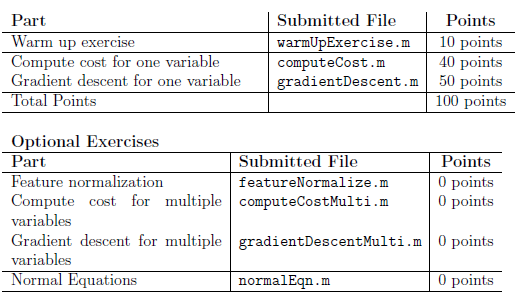

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.